clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## Paert 1: Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

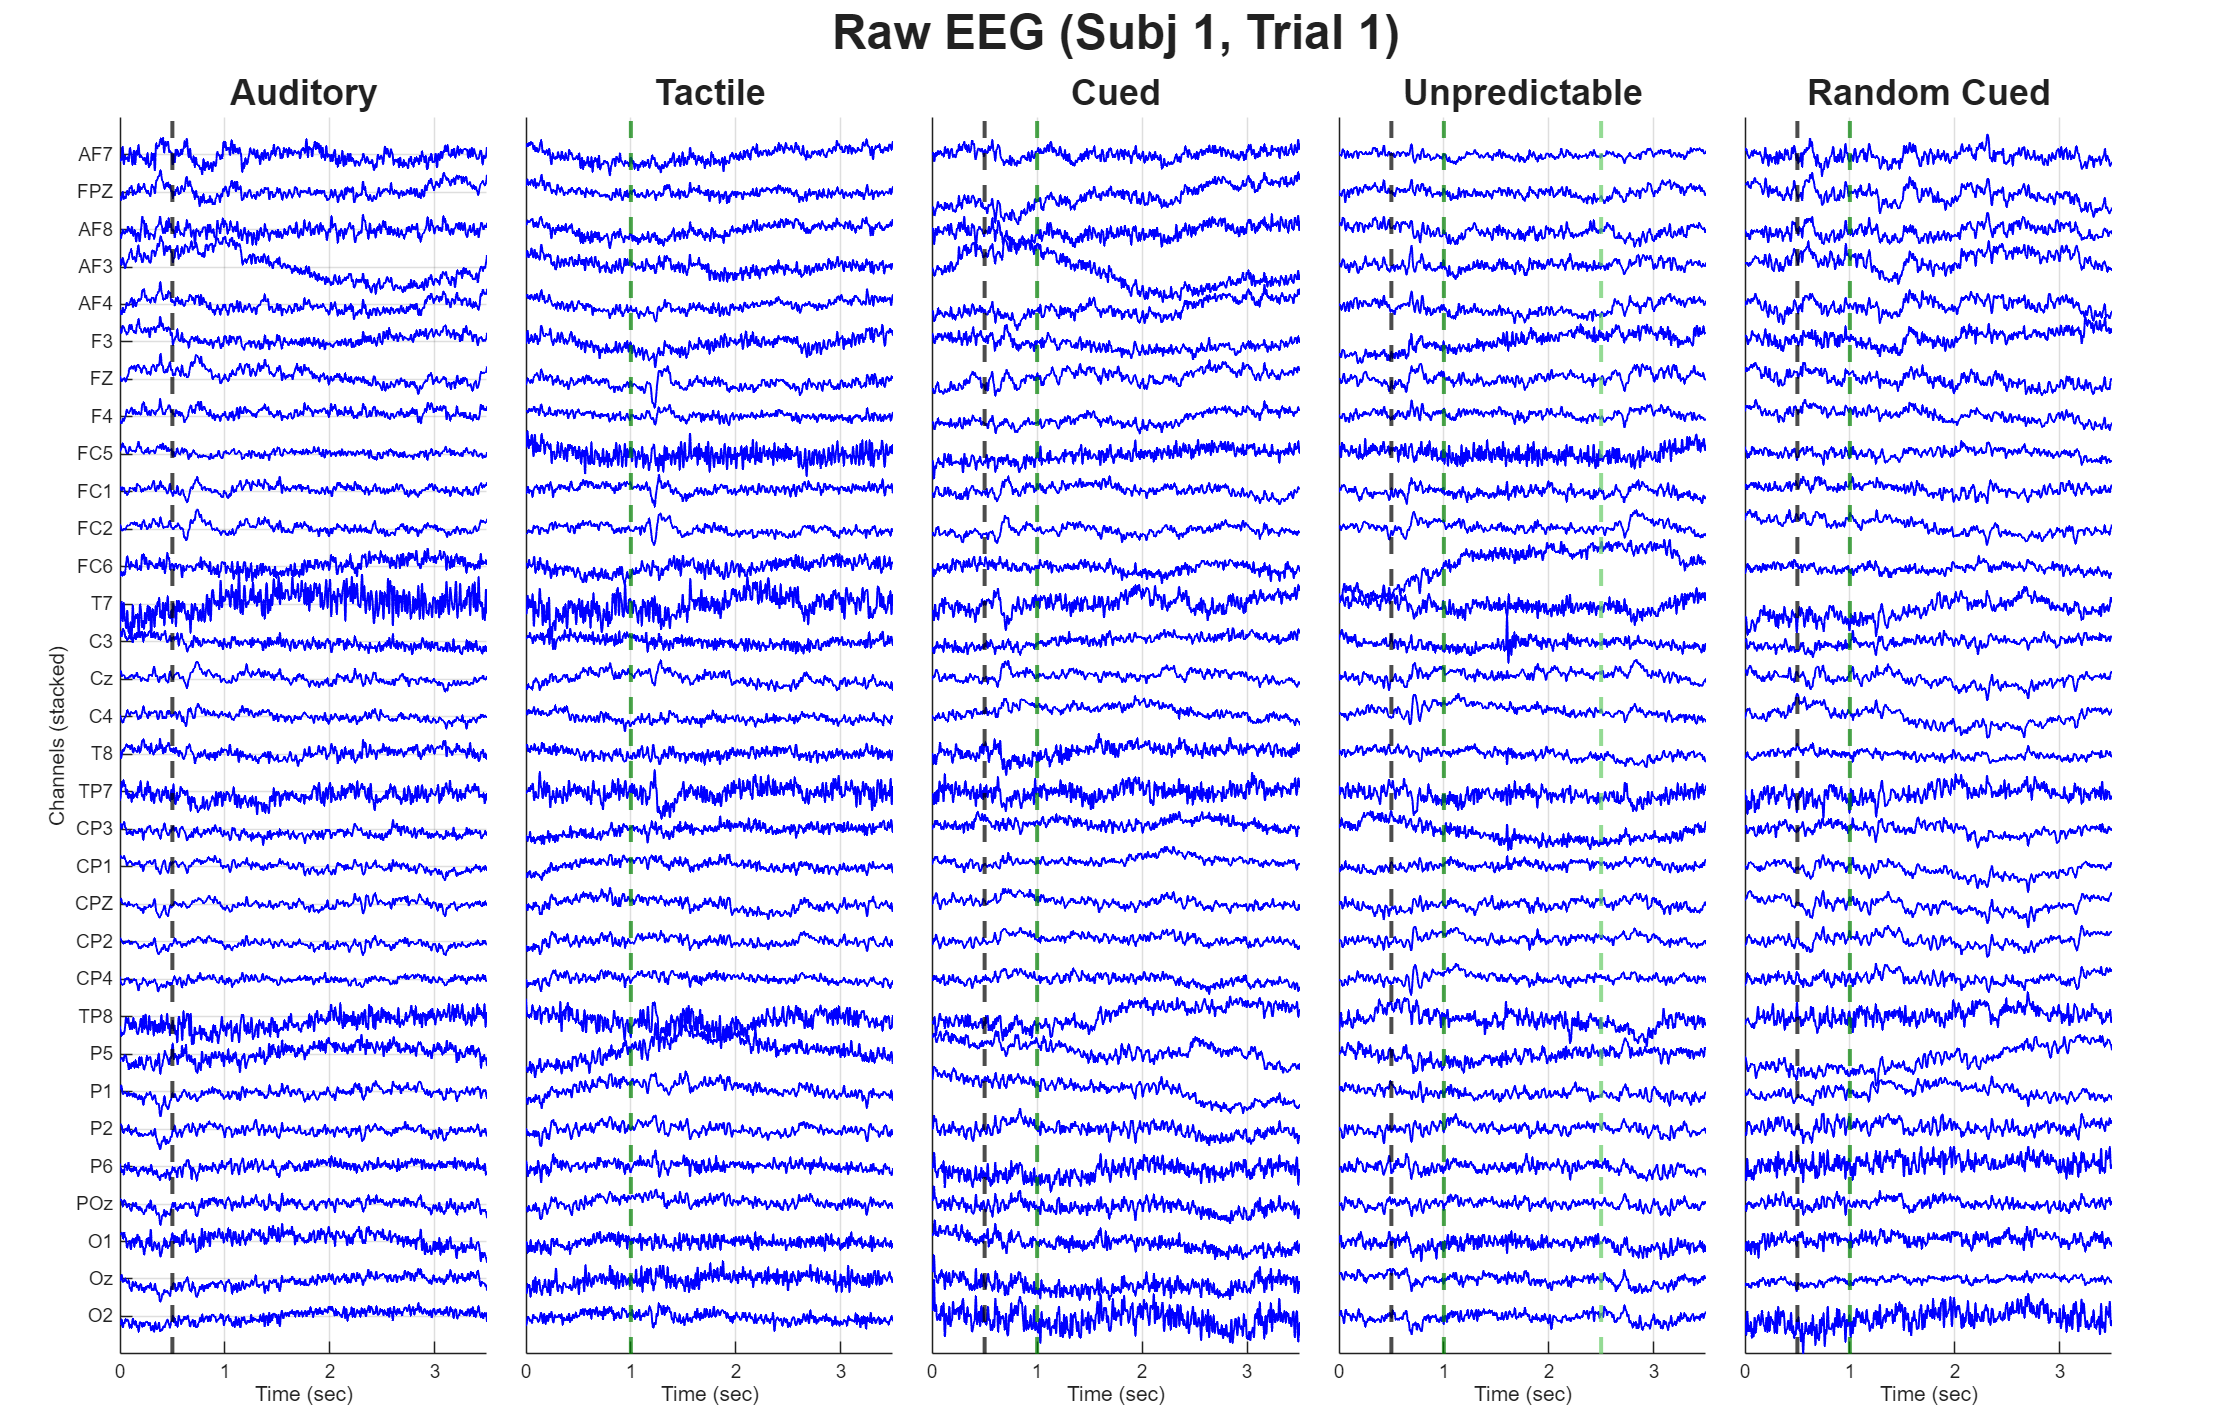

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials for each subject (Skipping Grand Average)...');

Calculating averages across trials for each subject (Skipping Grand Average)...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % Dynamically find the time dimension length from the first available subject
    if num_subjects > 0 && ~isempty(data_all_conds.(c_name){1})
        num_timepoints = size(data_all_conds.(c_name){1}, 2);
    else
        num_timepoints = expected_num_time;
    end
    
    % 1. Preallocate [Channels x Time x Subjects] using NaN to avoid zero-skewing missing data
    subj_avg_matrix = nan(num_ch, num_timepoints, num_subjects);
    
    for s = 1:num_subjects
        % Make sure the subject actually has data for this condition
        if ~isempty(data_all_conds.(c_name){s})
            % Average across dim 3 (trials) for THIS subject
            subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
        end
    end
    
    % Store the individual subject trial-averages
    data_subj_avg.(c_name) = subj_avg_matrix;
end

disp('Done! Data is stored in data_subj_avg with dimensions: [Channels x Time x Subjects].');

Done! Data is stored in data_subj_avg with dimensions: [Channels x Time x Subjects].


disp('Visualizing Trial Average with STD Shading for Subject 1...');

Visualizing Trial Average with STD Shading for Subject 1...


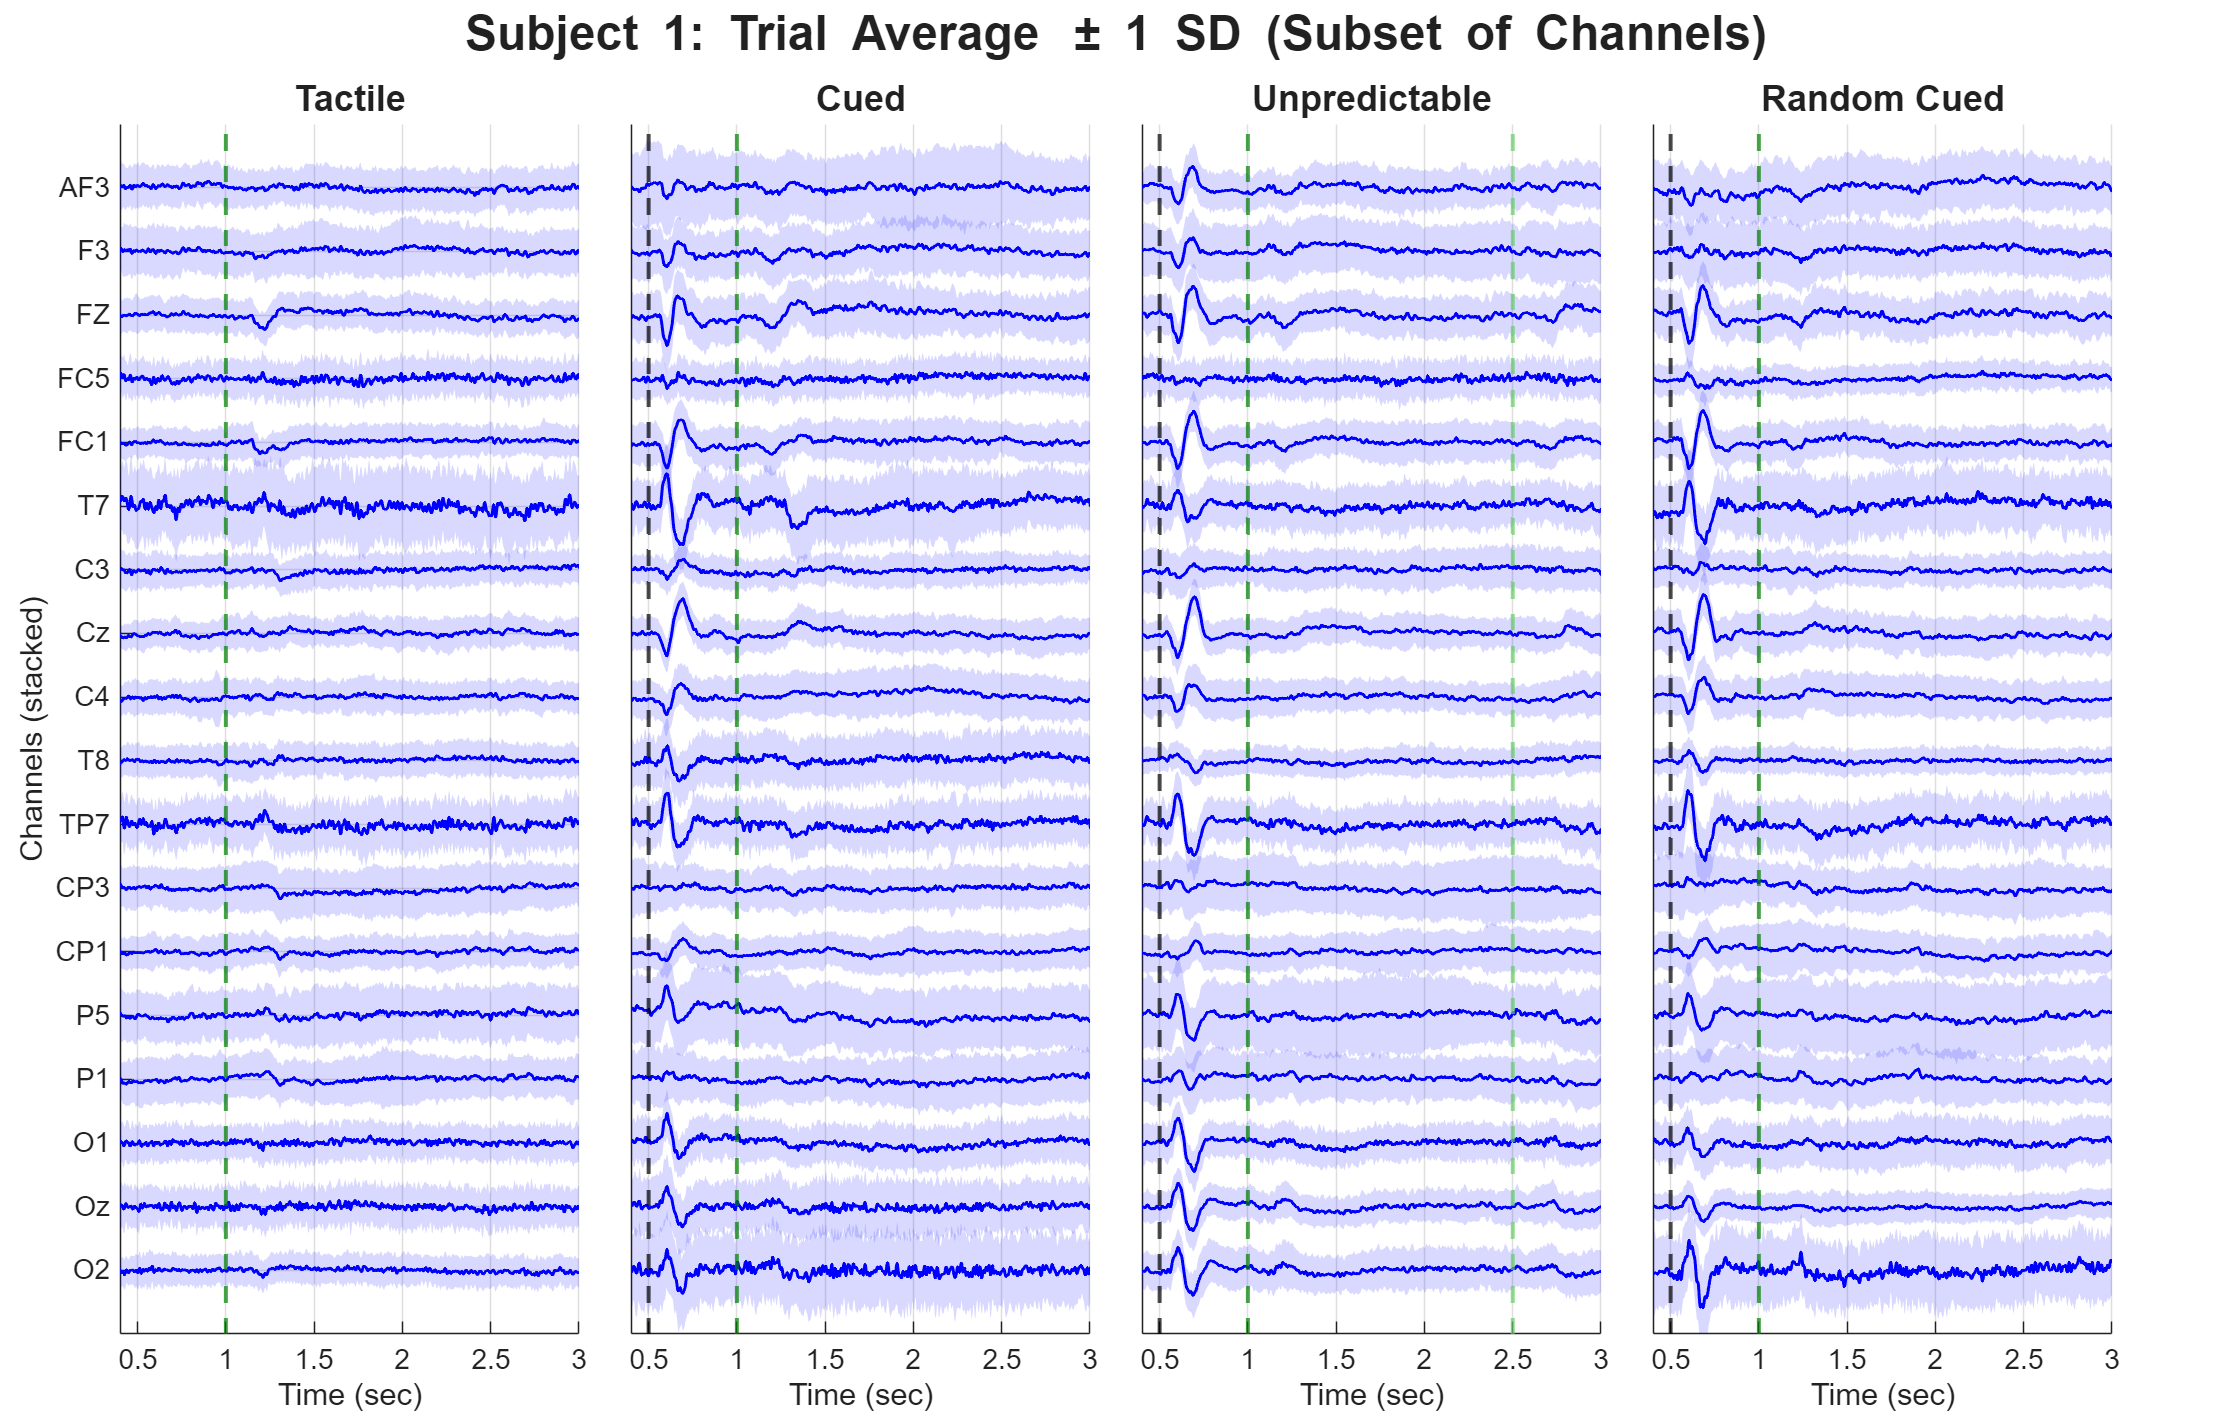


channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

% Safely define all_channels_str
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    all_channels_str = cellstr(num2str((1:num_ch)'));
end

[~, chan_idx] = ismember(channels_to_plot, all_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
base_conds_to_plot = {'BLT', 'P1', 'P2', 'P3'}; 
num_conds = length(base_conds_to_plot);

fig1 = figure('Position',[50 50 2200 1400]);
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Subject 1: Trial Average \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = base_conds_to_plot{c};
    
    % Extract raw trial data for Subject 1 [Channels x Time x Trials]
    subj1_data = data_all_conds.(cond_name){1}; 
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Calculate Mean and STD across the Trial dimension (dim 3)
        mu = squeeze(mean(subj1_data(actual_ch, :, :), 3, 'omitnan')) + y_shift;
        sigma = squeeze(std(subj1_data(actual_ch, :, :), 0, 3, 'omitnan'));
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    
    % Safe title assignment
    if strcmp(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif strcmp(cond_name, 'P1')
        plot_name = 'Cued';
    elseif strcmp(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif strcmp(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

## Part 2: Moving Window Functional Connectivity


disp('Step 1: Defining Window Parameters...');

Step 1: Defining Window Parameters...



% Ensure fs and time arrays are set (fallback to standard EEG values if empty)
if isempty(fs)
    warning('Sampling rate (fs) not found. Defaulting to 500 Hz.');
    fs = 500; 
end

% 1. Define Window Parameters
window_size_ms = 100;
step_size_ms = 50;

% Convert ms to samples based on your sampling rate
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

cond_names = fieldnames(data_subj_avg);
num_timepoints = size(data_subj_avg.(cond_names{1}), 2);
num_subjects = size(data_subj_avg.(cond_names{1}), 3);

% Create vector of starting indices for the sliding windows
start_idx = 1 : step_samples : (num_timepoints - win_samples + 1);
num_windows = length(start_idx);

% Calculate the center of each window in milliseconds (for plotting the X-axis)
window_centers_ms = zeros(1, num_windows);
for w = 1:num_windows
    % Averages the time_ms_eeg values within the current window chunk
    window_centers_ms(w) = mean(time_ms_eeg(start_idx(w) : start_idx(w) + win_samples - 1));
end


## Step 1.3: 

function [num_factors, map_values] = velicer_map(data, quiet)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.
%
% Inputs:
%   data  - An (n x p) matrix of raw data (n observations, p variables).
%   quiet - Boolean flag. Set to true to suppress plotting (default: false).

    if nargin < 2
        quiet = false; % Default is to show the plot
    end

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    eigval = diag(eigval_mat);
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = eigvec(:, idx);
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        part_cov = R - (A * A');
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        R_partial_off = R_partial - eye(p);
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Optional: Plot the results to visualize the minimum
    if ~quiet
        figure('Position',[50 50 800 500]);
        plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
        hold on;
        plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); 
        coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
        text(num_factors, 0.2, coordinate_text, 'VerticalAlignment', 'top', ...
            'HorizontalAlignment', 'center', 'FontSize', 26, 'FontWeight', 'bold', 'Color', 'r');
        xlabel('Number of Factors Retained');
        ylabel('Avg. Sqrd. Partial Corr.');
        title('Velicer''s MAP Test');
        legend('MAP Values', 'Minimum (Optimal Factors)');
        set(gca,'FontSize',24);
        grid on; hold off;
    end
end


## Step 2 & 3: Pairwise dPCA and Connectivity Heatmaps

%% Step 2 & 3: Pairwise dPCA and Connectivity Heatmaps (Custom Windows)
disp('Running Pairwise dPCA and Generating Correlation Heatmaps...');

Running Pairwise dPCA and Generating Correlation Heatmaps...


Pair Auditory vs Cued (Window 0.50s to 0.85s): MAP selected k=5 shared components


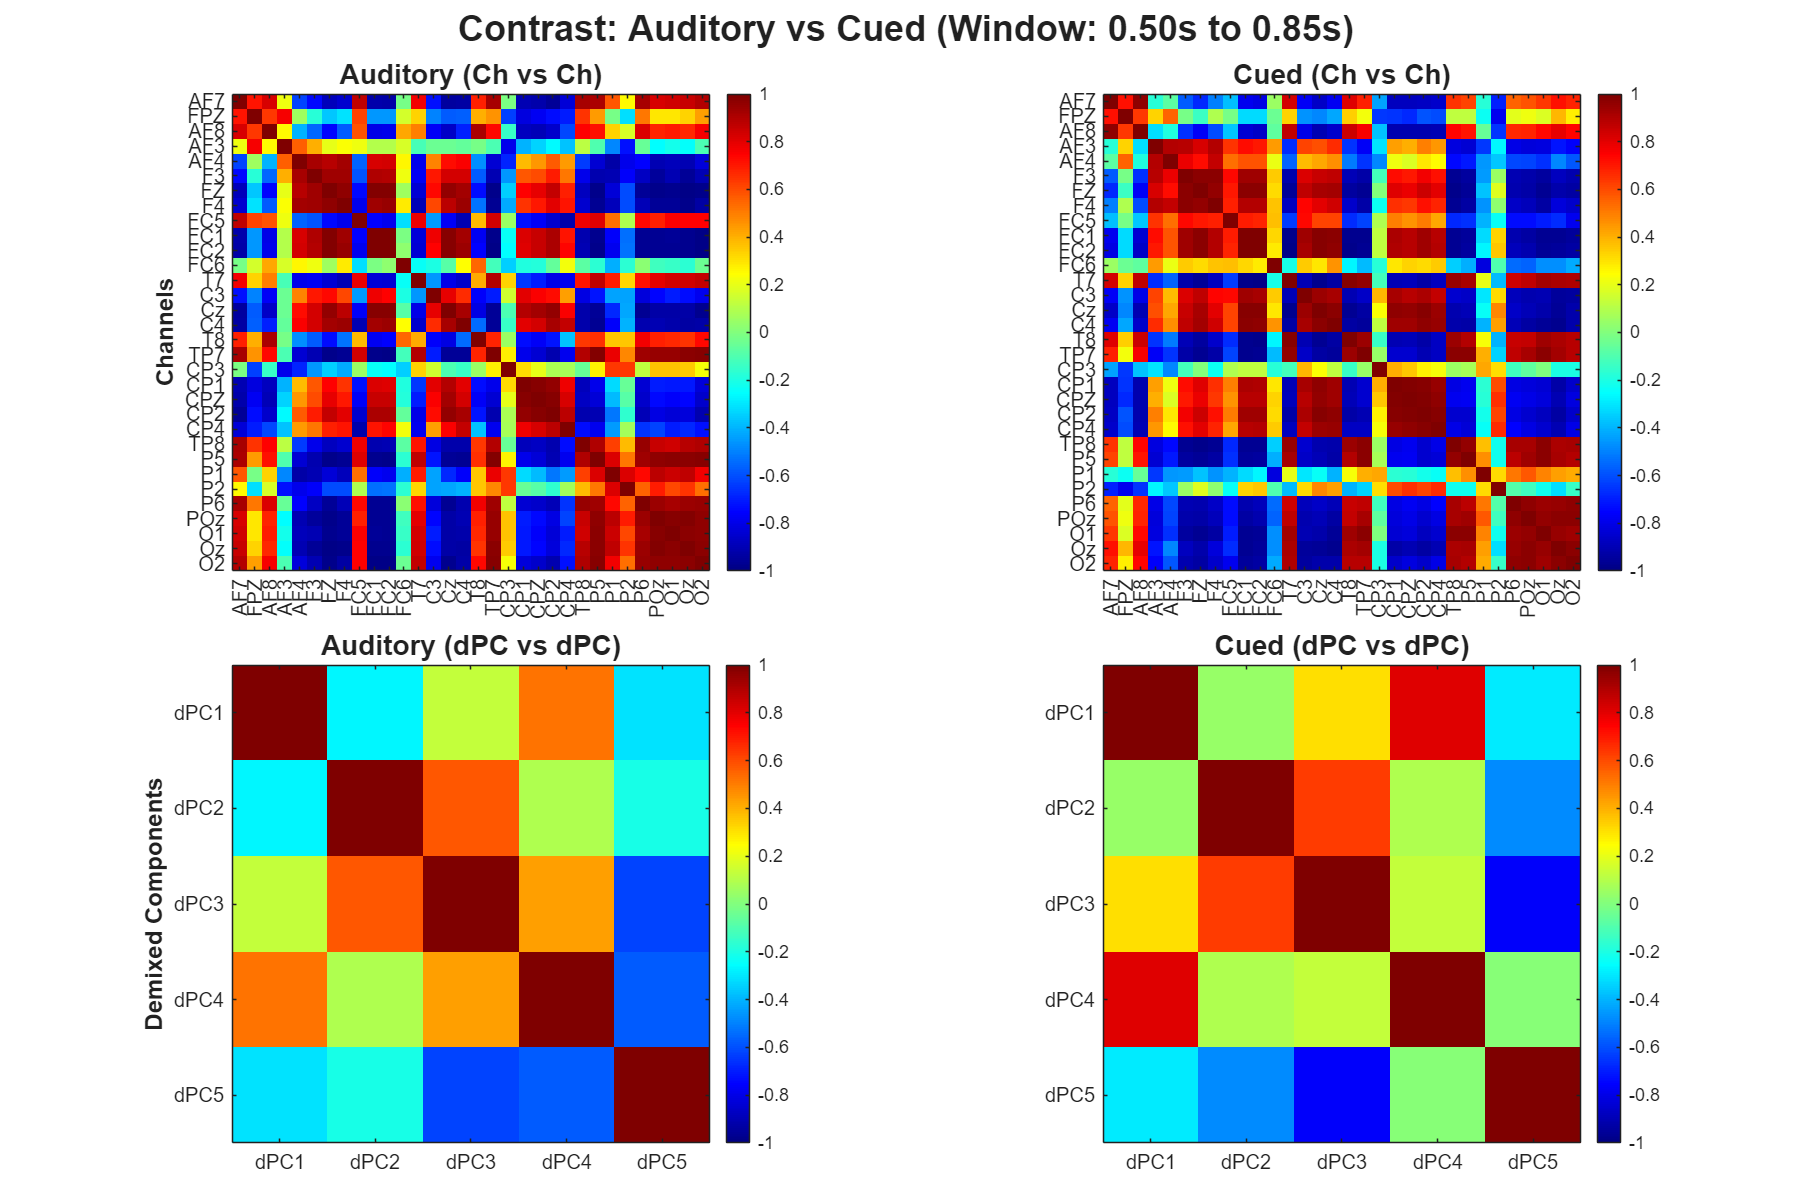

Pair Tactile vs Cued (Window 1.00s to 1.35s): MAP selected k=10 shared components


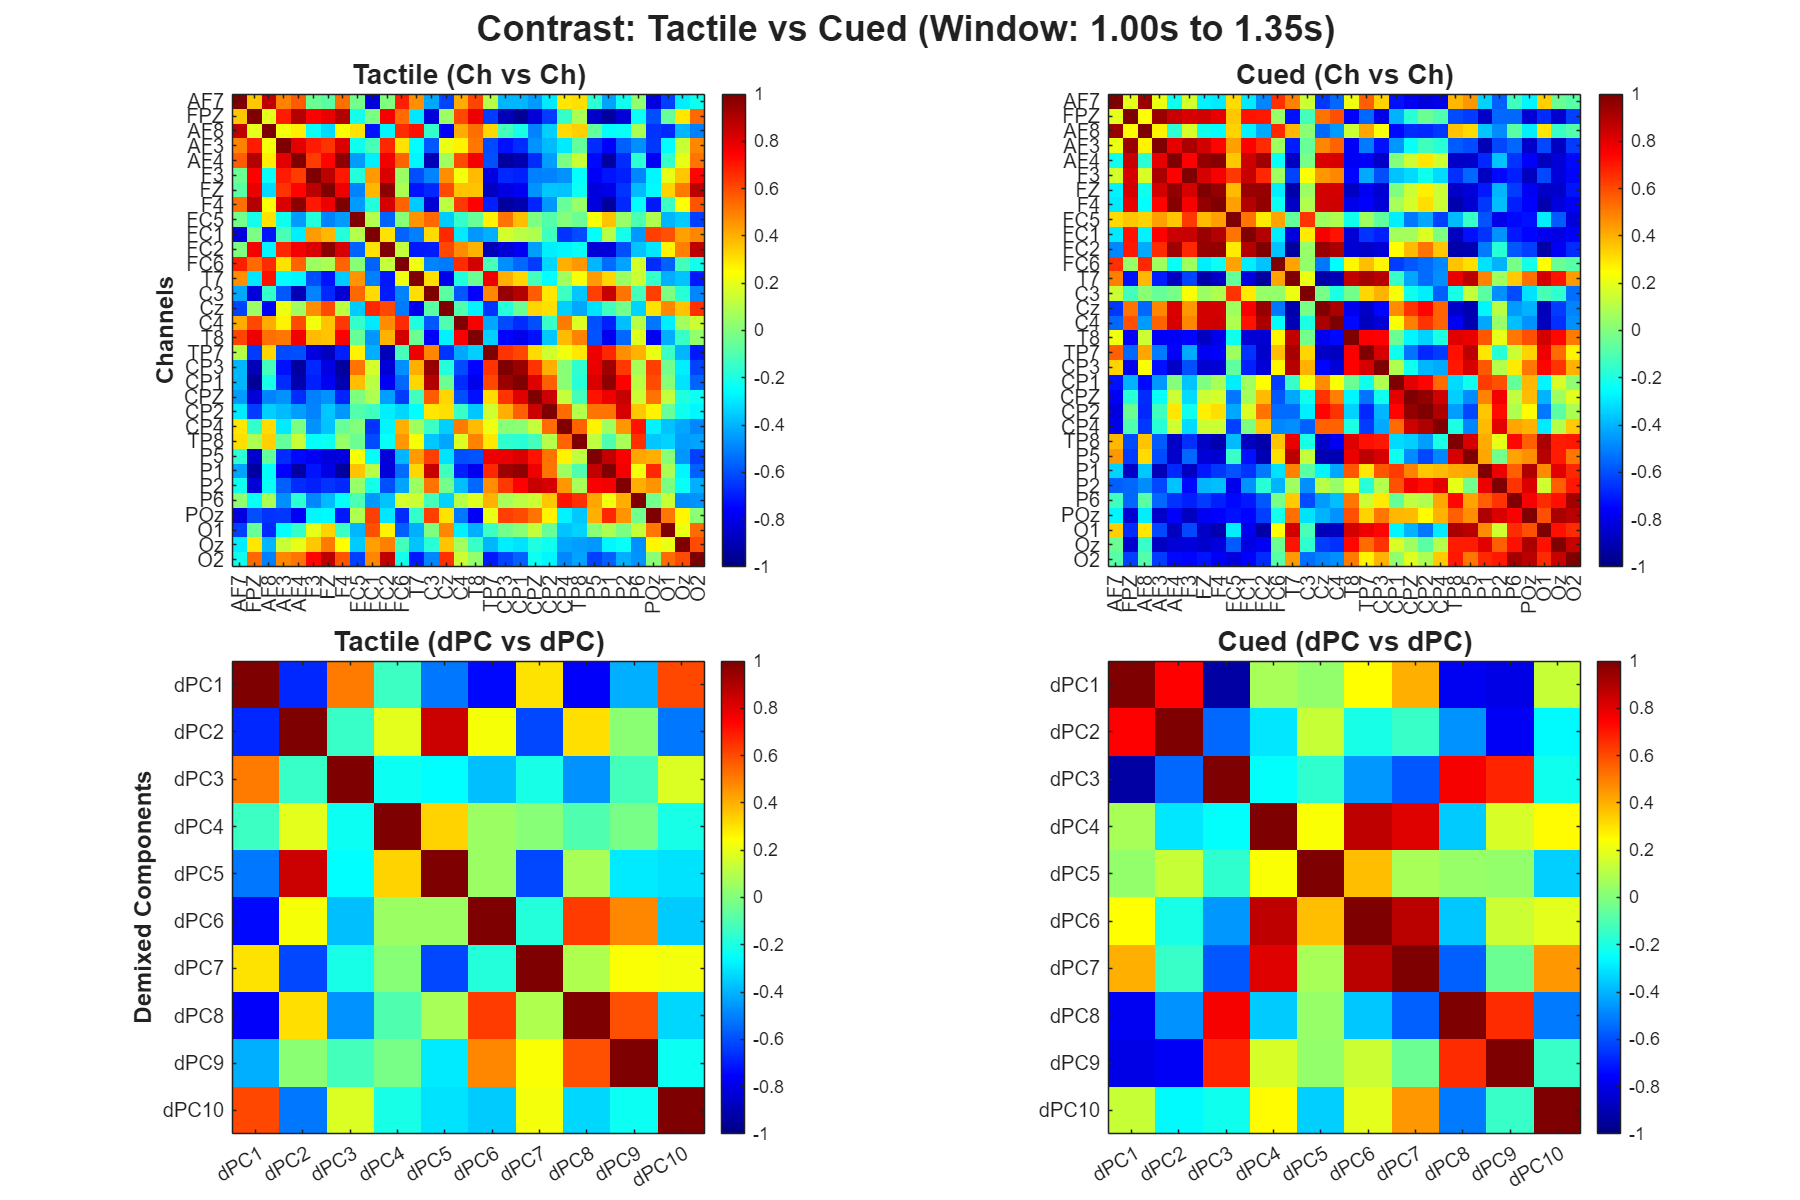

Pair Cued vs Unpred. 500 (Window 0.50s to 0.85s): MAP selected k=8 shared components


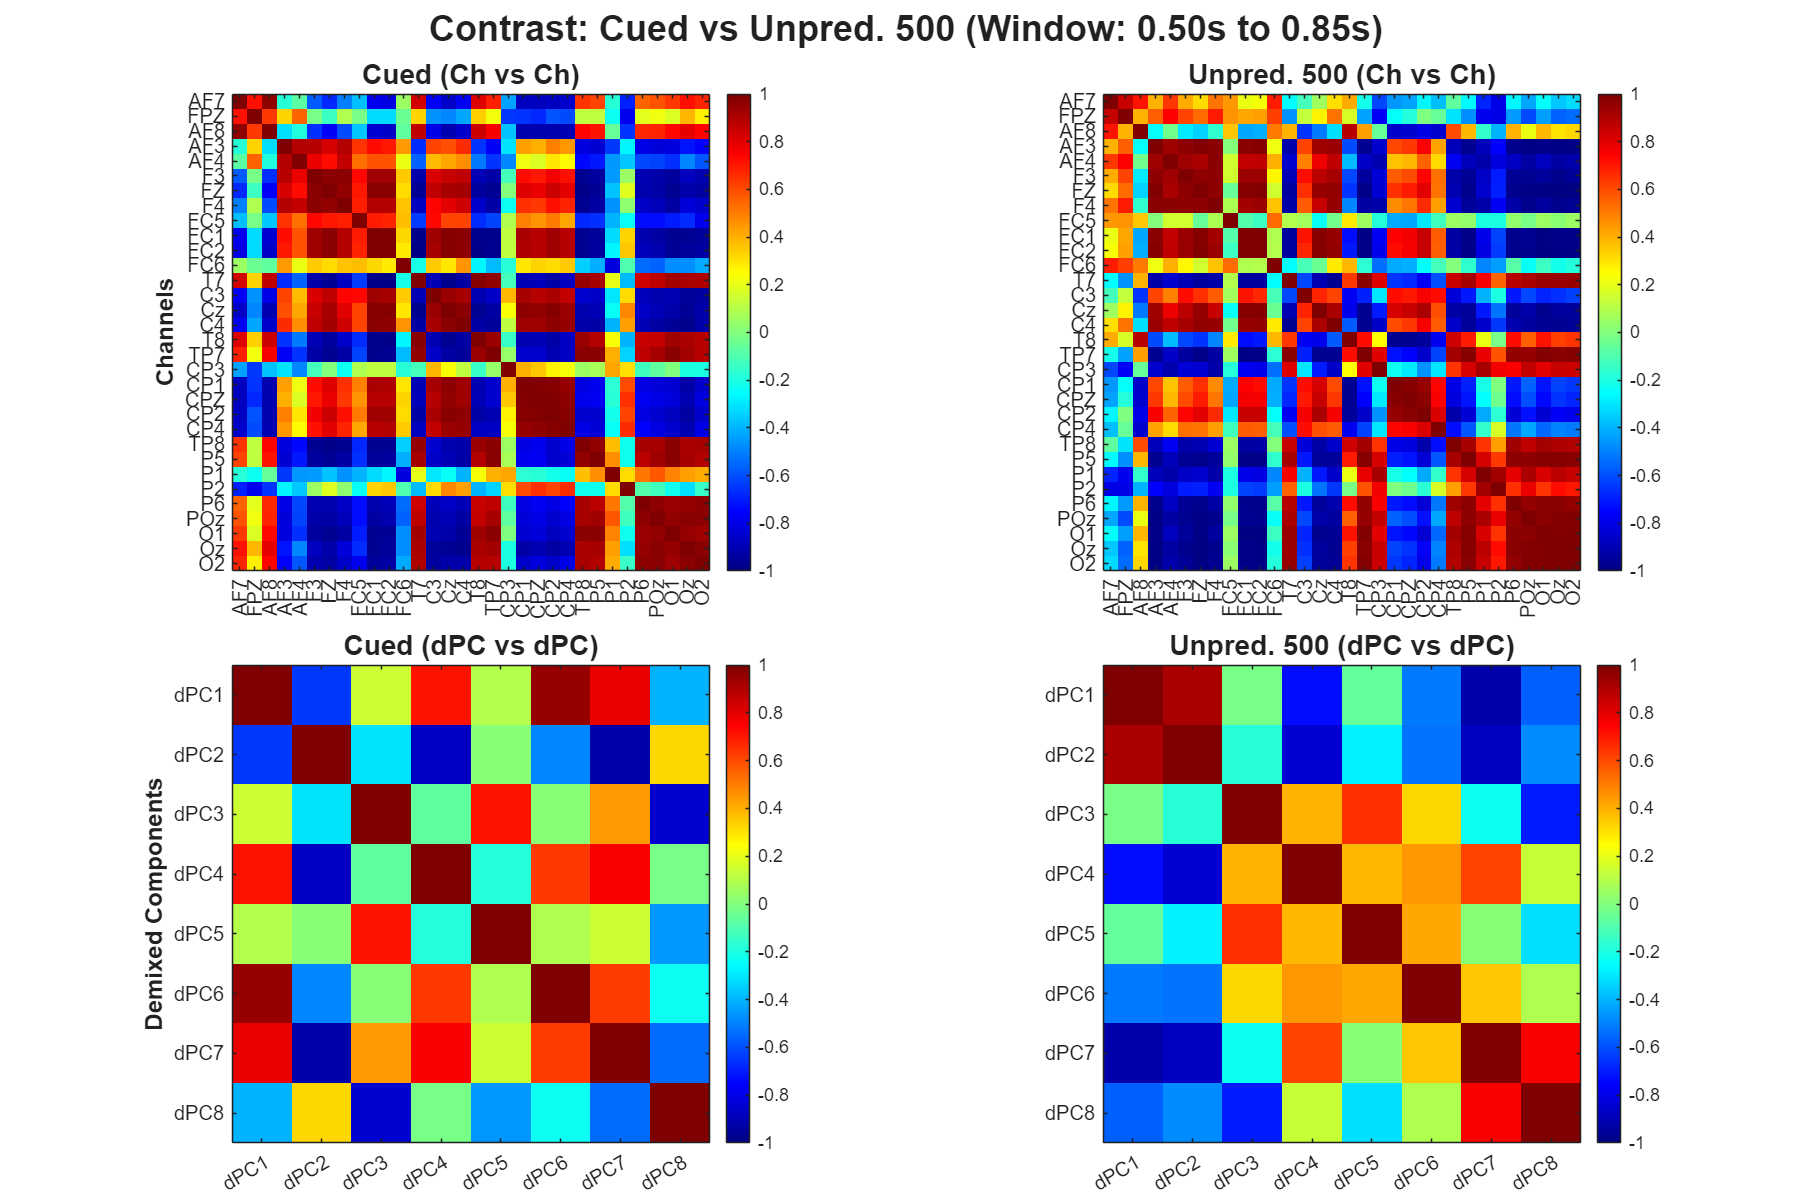

Pair Cued vs Unpred. 2000 (Window 0.50s to 2.85s): MAP selected k=7 shared components


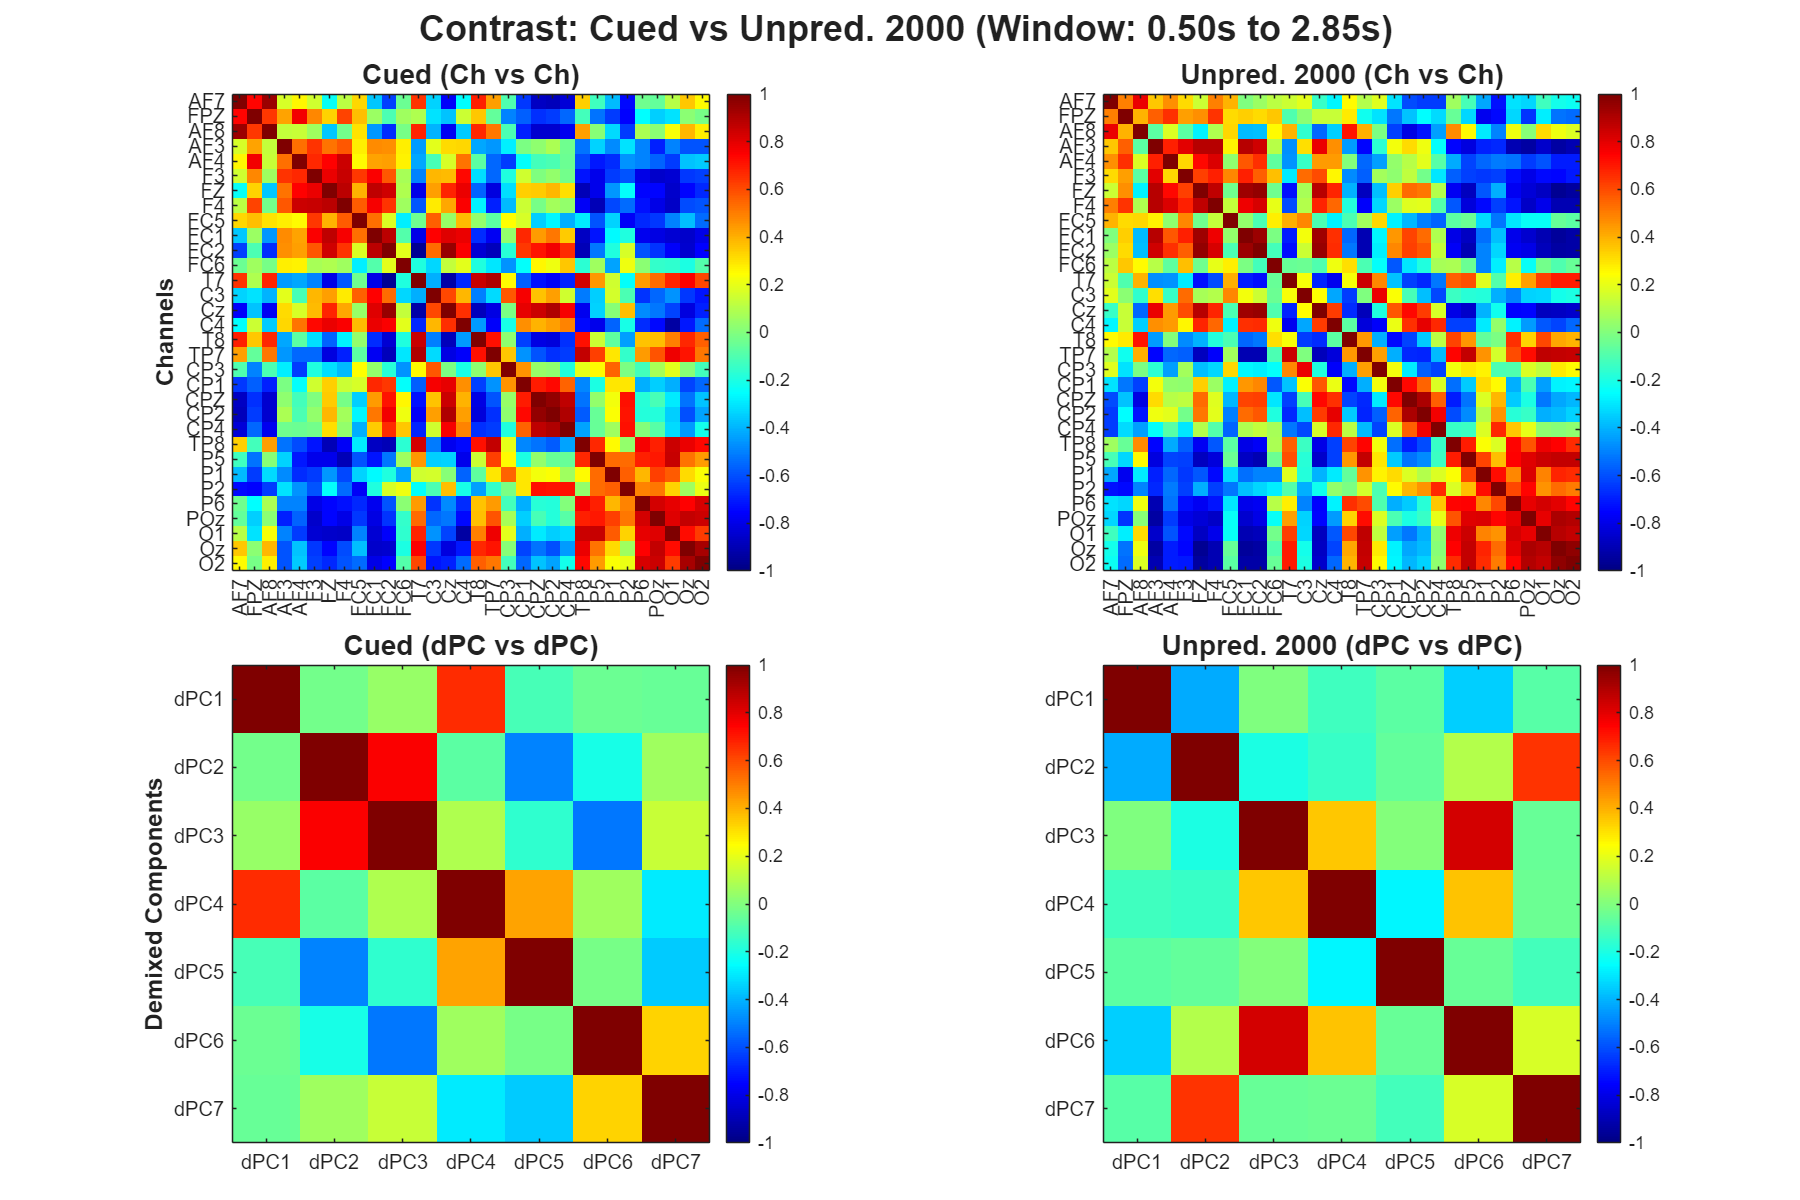

Pair Cued vs Rand. Cued 500 (Window 0.50s to 0.85s): MAP selected k=8 shared components


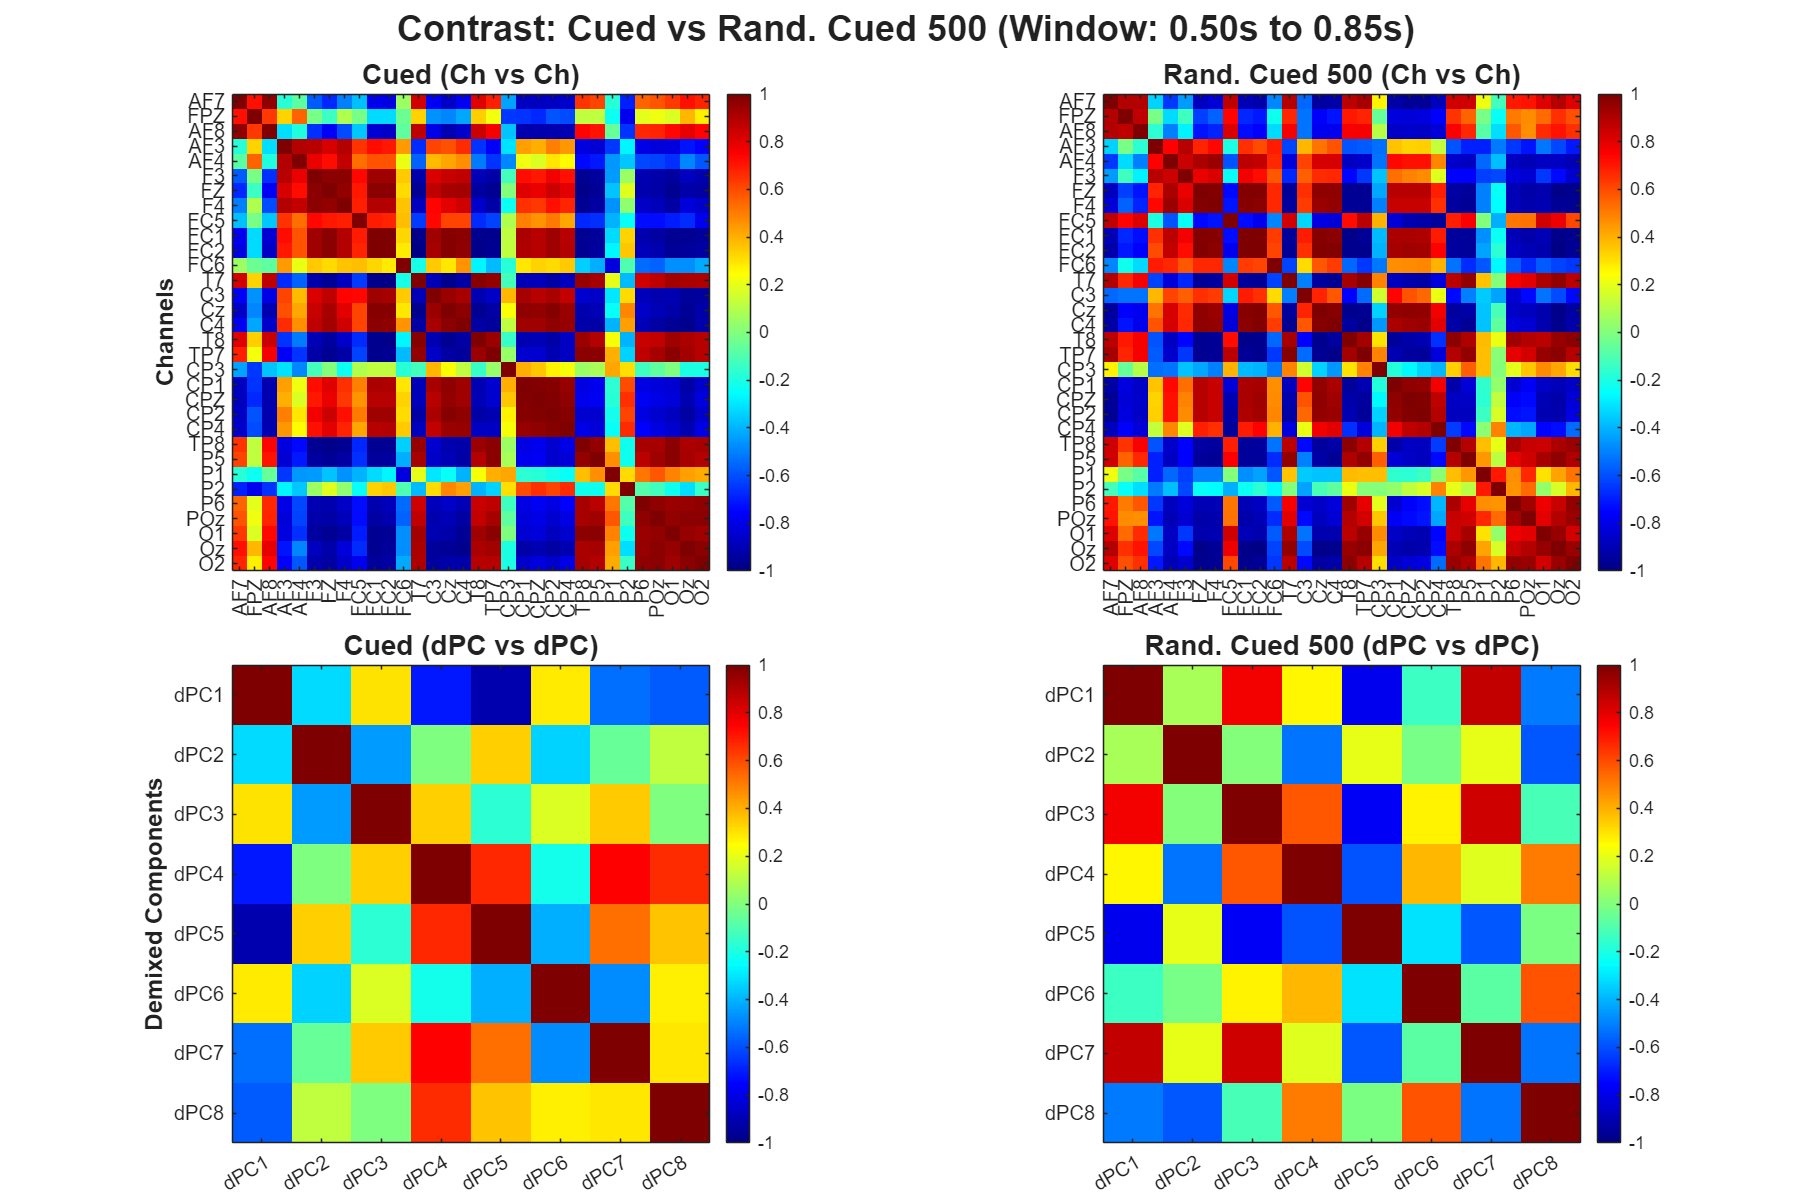

Pair Cued vs Rand. Cued missing (Window 0.50s to 0.85s): MAP selected k=8 shared components


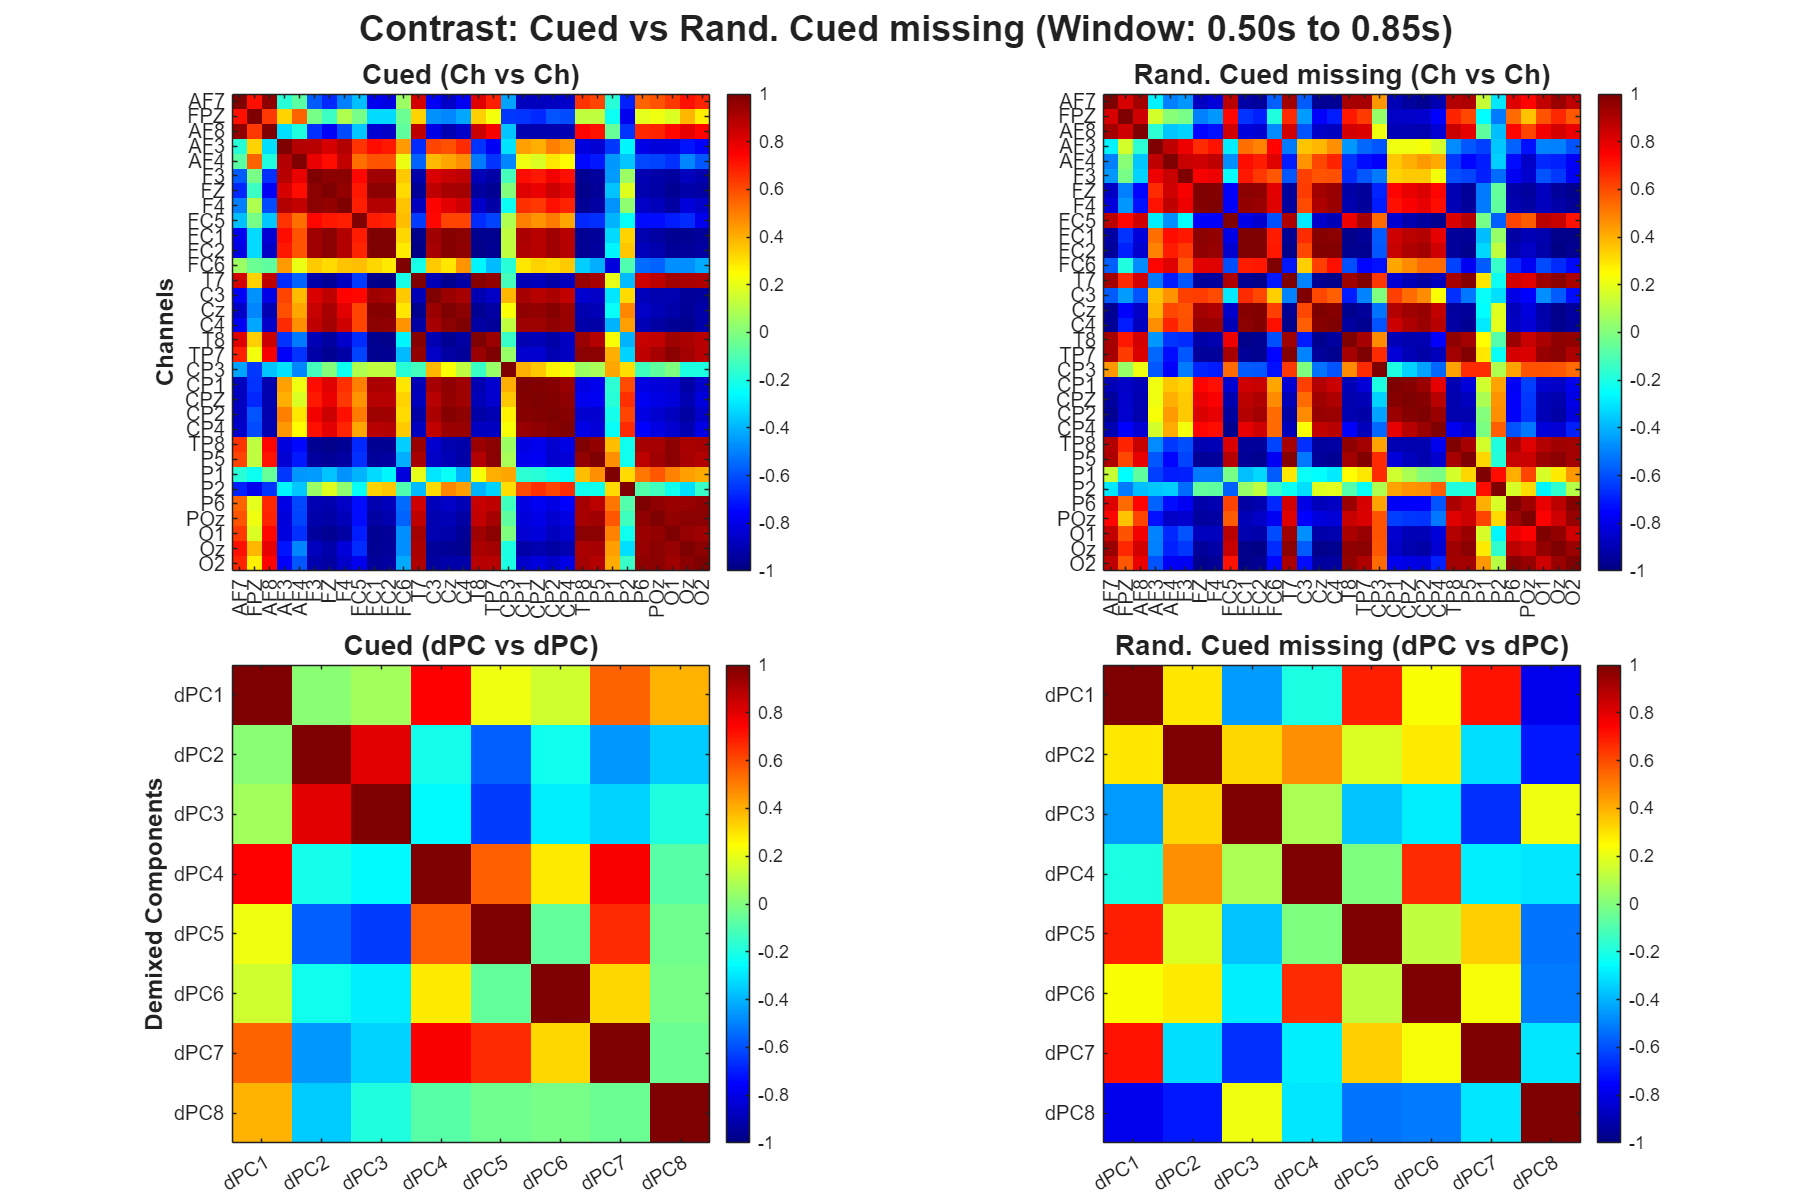


% Inline helper function: cleans condition names for plotting
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs along with their specific time windows [start_sec, end_sec]
pairs = {
    {'BLA', 'P1', [0.5, 0.85]},
    {'BLT', 'P1', [1.0, 1.35]},
    {'P1', 'P2_500', [0.5, 0.85]},
    {'P1', 'P2_2000', [0.5, 2.85]},
    {'P1', 'P3_500', [0.5, 0.85]},
    {'P1', 'P3_missing', [0.5, 0.85]}
};

target_subj = 1; % Analyzing Subject 1

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3}; % Extract the specific time window for this pair
    
    % Clean the names for all plotting and console output
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    % Find precise indices for the specified time window dynamically for this pair
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');

    % Ensure both conditions actually exist in the dataset for Subject 1
    if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % Extract Full Trial-Averaged Data for Subject 1 [Channels x Time]
    dataA = data_subj_avg.(condA)(:, :, target_subj);
    dataB = data_subj_avg.(condB)(:, :, target_subj);
    
    if all(isnan(dataA(:))) || all(isnan(dataB(:)))
        continue;
    end
    
    %% --- DIMENSIONALITY REDUCTION (SHARED MANIFOLD) ---
    
    % 1. Concatenate conditions horizontally [Channels x (Time*2)]
    data_combined = [dataA, dataB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    % 2. Find optimal k for the shared space using Velicer's MAP
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end % Safe fallback
    
    fprintf('Pair %s vs %s (Window %.2fs to %.2fs): MAP selected k=%d shared components\n', ...
        cleanA, cleanB, t_win(1), t_win(2), k_opt);
    
    % 3. Extract Unmixing Matrix (W)
    try
        % dPCA expects [Channels x Time x Conditions]
        X_dpca = cat(3, dataA, dataB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        
        % Minimal dPCA call (assuming dpca toolbox is in path)
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        
        % Transpose dPCA's W from [Channels x k] to [k x Channels]
        W = W_dpca';
        
    catch ME
        % FALLBACK: Shared PCA 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; % Unmixing matrix [k_opt x Channels]
    end
    
    % 4. Project Cond A and Cond B into the EXACT SAME latent space
    compA = W * (dataA - mean(dataA, 2)); 
    compB = W * (dataB - mean(dataB, 2));
    
    %% --- SLIDING WINDOW CORRELATION (EXTRACTION) ---
    
    % Extract the specific time window chunks for this pair
    ch_chunkA = dataA(:, idx_start:idx_end);
    ch_chunkB = dataB(:, idx_start:idx_end);
    
    pc_chunkA = compA(:, idx_start:idx_end);
    pc_chunkB = compB(:, idx_start:idx_end);
    
    % Correlate (Transpose so variables are columns)
    corr_ch_A = corrcoef(ch_chunkA');
    corr_ch_B = corrcoef(ch_chunkB');
    
    corr_pc_A = corrcoef(pc_chunkA');
    corr_pc_B = corrcoef(pc_chunkB');
    
    %% --- PLOTTING CONTRAST HEATMAPS ---
    
    fig = figure('Position', [100, 100, 1200, 800], 'Name', sprintf('%s vs %s', cleanA, cleanB));
    tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % --- Row 1: Channel Connectivity ---
    % Cond A (Channels)
    nexttile; imagesc(corr_ch_A); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (Ch vs Ch)', cleanA), 'FontSize', 14);
    axis square; ylabel('Channels', 'FontSize', 12, 'FontWeight', 'bold');
    yticks(1:num_ch); yticklabels(all_channels_str); xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
    
    % Cond B (Channels)
    nexttile; imagesc(corr_ch_B); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (Ch vs Ch)', cleanB), 'FontSize', 14);
    axis square;
    yticks(1:num_ch); yticklabels(all_channels_str); xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
    
    % --- Row 2: dPC Connectivity ---
    % Cond A (dPCs)
    nexttile; imagesc(corr_pc_A); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (dPC vs dPC)', cleanA), 'FontSize', 14);
    axis square; ylabel('Demixed Components', 'FontSize', 12, 'FontWeight', 'bold');
    yticks(1:k_opt); yticklabels(pc_labels); xticks(1:k_opt); xticklabels(pc_labels);
    
    % Cond B (dPCs)
    nexttile; imagesc(corr_pc_B); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (dPC vs dPC)', cleanB), 'FontSize', 14);
    axis square;
    yticks(1:k_opt); yticklabels(pc_labels); xticks(1:k_opt); xticklabels(pc_labels);
    
    % Master Title
    sgtitle(sprintf('Contrast: %s vs %s (Window: %.2fs to %.2fs)', ...
        cleanA, cleanB, t_win(1), t_win(2)), ...
        'FontSize', 18, 'FontWeight', 'bold');
end


disp('Pairwise Heatmaps generated successfully.');

Pairwise Heatmaps generated successfully.


Pairwise Heatmaps generated successfully.


## Steps 4, 5, & 6: Connectivity Metric Extraction and Grouped Bar Charts

%% Steps 4, 5, & 6: Connectivity Metric Extraction and Grouped Bar Charts
disp('Extracting Global Mean Connectivity and Plotting per Group...');

Extracting Global Mean Connectivity and Plotting per Group...


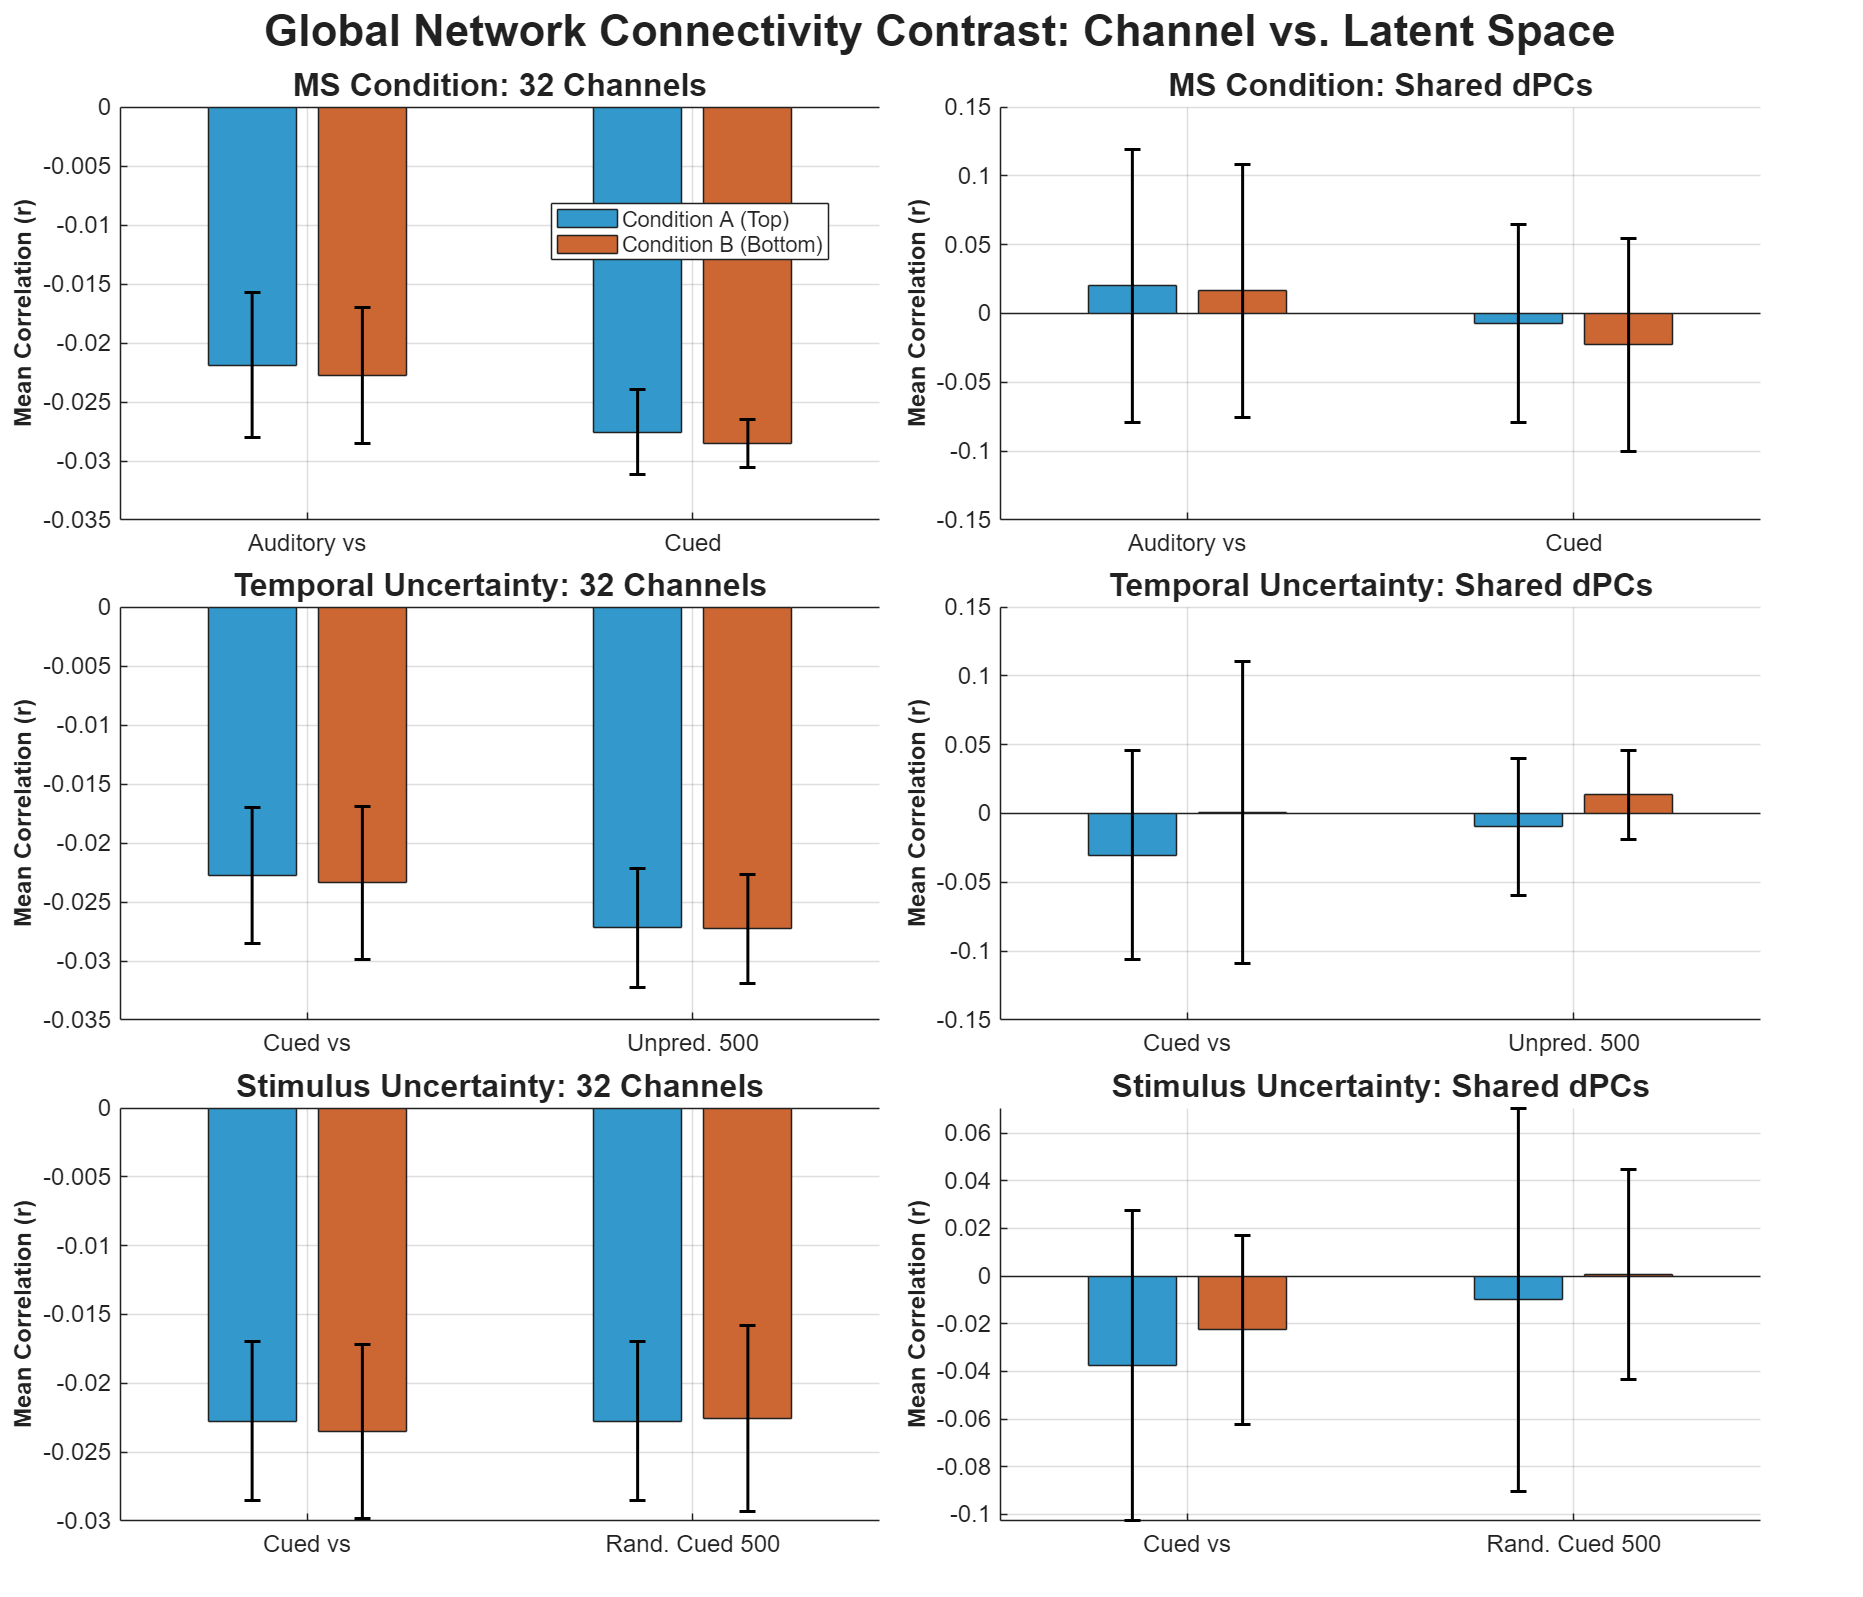


% Inline helper function: gets mean of the upper triangle of a correlation matrix
get_upper_tri_mean = @(mat) mean(mat(triu(true(size(mat)), 1)), 'omitnan');

% Inline helper function: cleans condition names for plotting
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define the 3 Experimental Groups with their specific pairs and windows
stats_groups = struct();

% Group 1: MS Condition
stats_groups(1).name = 'MS Condition';
stats_groups(1).pairs = {
    {'BLA', 'P1', [0.5, 0.85]},
    {'BLT', 'P1', [1.0, 1.35]}
};

% Group 2: Temporal Uncertainty
stats_groups(2).name = 'Temporal Uncertainty';
stats_groups(2).pairs = {
    {'P1', 'P2_500', [0.5, 0.85]},
    {'P1', 'P2_2000', [0.5, 2.85]}
};

% Group 3: Stimulus Uncertainty
stats_groups(3).name = 'Stimulus Uncertainty';
stats_groups(3).pairs = {
    {'P1', 'P3_500', [0.5, 0.85]},
    {'P1', 'P3_missing', [0.5, 0.85]}
};

% Create a large figure for all 3 groups (3 rows x 2 columns)
fig_conn = figure('Position', [50 50 1400 1200]);
t = tiledlayout(length(stats_groups), 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Global Network Connectivity Contrast: Channel vs. Latent Space', 'FontSize', 22, 'FontWeight', 'bold');

for g = 1:length(stats_groups)
    num_pairs = length(stats_groups(g).pairs);
    
    % Preallocate arrays for this group [Pairs x Subjects]
    mean_ch_A = nan(num_pairs, num_subjects);
    mean_ch_B = nan(num_pairs, num_subjects);
    mean_pc_A = nan(num_pairs, num_subjects);
    mean_pc_B = nan(num_pairs, num_subjects);
    
    pair_labels = cell(1, num_pairs);
    
    for p = 1:num_pairs
        condA = stats_groups(g).pairs{p}{1};
        condB = stats_groups(g).pairs{p}{2};
        t_win = stats_groups(g).pairs{p}{3}; 
        
        % Clean the names and format the label for the X-axis
        cleanA = get_clean_name(condA);
        cleanB = get_clean_name(condB);
        pair_labels{p} = sprintf('%s vs\n%s', cleanA, cleanB);
        
        % Find exact indices for this pair's specific time window
        idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
        idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
        
        % Process ALL subjects to build statistical variance
        for s = 1:num_subjects
            % Safeguard against missing subjects/conditions
            if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
                continue; 
            end
            
            dataA = data_subj_avg.(condA)(:, :, s);
            dataB = data_subj_avg.(condB)(:, :, s);
            
            if all(isnan(dataA(:))) || all(isnan(dataB(:))), continue; end
            
            % 1. Create Shared Manifold
            data_combined = [dataA, dataB];
            data_combined_centered = data_combined - mean(data_combined, 2);
            
            % 2. Velicer's MAP to find shared k
            [k_opt, ~] = velicer_map(data_combined_centered', true);
            if k_opt < 2, k_opt = 2; end 
            
            % 3. Extract Unmixing Matrix (Shared PCA)
            [~, ~, V] = svd(data_combined_centered', 'econ');
            W = V(:, 1:k_opt)'; 
            
            % 4. Project both conditions into the shared space
            compA = W * (dataA - mean(dataA, 2)); 
            compB = W * (dataB - mean(dataB, 2));
            
            % 5. Correlate specific time windows (Transpose to match variables)
            corr_ch_A = corrcoef(dataA(:, idx_start:idx_end)');
            corr_ch_B = corrcoef(dataB(:, idx_start:idx_end)');
            corr_pc_A = corrcoef(compA(:, idx_start:idx_end)');
            corr_pc_B = corrcoef(compB(:, idx_start:idx_end)');
            
            % 6. Extract the Global Mean (Upper Triangle)
            mean_ch_A(p, s) = get_upper_tri_mean(corr_ch_A);
            mean_ch_B(p, s) = get_upper_tri_mean(corr_ch_B);
            mean_pc_A(p, s) = get_upper_tri_mean(corr_pc_A);
            mean_pc_B(p, s) = get_upper_tri_mean(corr_pc_B);
        end
    end
    
    % Calculate Grand Means and Standard Deviations across subjects for this group
    mu_ch  = [mean(mean_ch_A, 2, 'omitnan'), mean(mean_ch_B, 2, 'omitnan')];
    std_ch = [std(mean_ch_A, 0, 2, 'omitnan'), std(mean_ch_B, 0, 2, 'omitnan')];

    mu_pc  = [mean(mean_pc_A, 2, 'omitnan'), mean(mean_pc_B, 2, 'omitnan')];
    std_pc = [std(mean_pc_A, 0, 2, 'omitnan'), std(mean_pc_B, 0, 2, 'omitnan')];
    
    %% Plotting Row for this Group
    
    % --- Left Column: Channel-Level Contrast ---
    nexttile; hold on;
    b_ch = bar(mu_ch, 'grouped');
    b_ch(1).FaceColor = [0.2 0.6 0.8]; % Blueish
    b_ch(2).FaceColor = [0.8 0.4 0.2]; % Orangeish

    % Add Error Bars
    for i = 1:2
        x_pos = b_ch(i).XEndPoints;
        errorbar(x_pos, mu_ch(:,i), std_ch(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    end

    set(gca, 'xtick', 1:num_pairs, 'xticklabel', pair_labels, 'FontSize', 12);
    ylabel('Mean Correlation (r)', 'FontSize', 12, 'FontWeight', 'bold');
    title(sprintf('%s: 32 Channels', stats_groups(g).name), 'FontSize', 16);
    if g == 1, legend({'Condition A (Top)', 'Condition B (Bottom)'}, 'Location', 'best'); end
    grid on; hold off;

    % --- Right Column: Latent Component Contrast ---
    nexttile; hold on;
    b_pc = bar(mu_pc, 'grouped');
    b_pc(1).FaceColor = [0.2 0.6 0.8]; 
    b_pc(2).FaceColor = [0.8 0.4 0.2]; 

    % Add Error Bars
    for i = 1:2
        x_pos = b_pc(i).XEndPoints;
        errorbar(x_pos, mu_pc(:,i), std_pc(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    end

    set(gca, 'xtick', 1:num_pairs, 'xticklabel', pair_labels, 'FontSize', 12);
    ylabel('Mean Correlation (r)', 'FontSize', 12, 'FontWeight', 'bold');
    title(sprintf('%s: Shared dPCs', stats_groups(g).name), 'FontSize', 16);
    grid on; hold off;
end

% Save output
saveas(fig_conn, fullfile(output_path, 'Grouped_Connectivity_Statistical_Contrast.png'));

disp('Analysis Complete! Grouped Statistical Contrast Bar Charts saved to output directory.');

Analysis Complete! Grouped Statistical Contrast Bar Charts saved to output directory.


Analysis Complete! Grouped Statistical Contrast Bar Charts saved to output directory.


## Pairwise dPCA & Moving Window Heatmaps (Specific Sub-Windows)

disp('Running Pairwise dPCA and Specific Window Heatmaps...');

Running Pairwise dPCA and Specific Window Heatmaps...


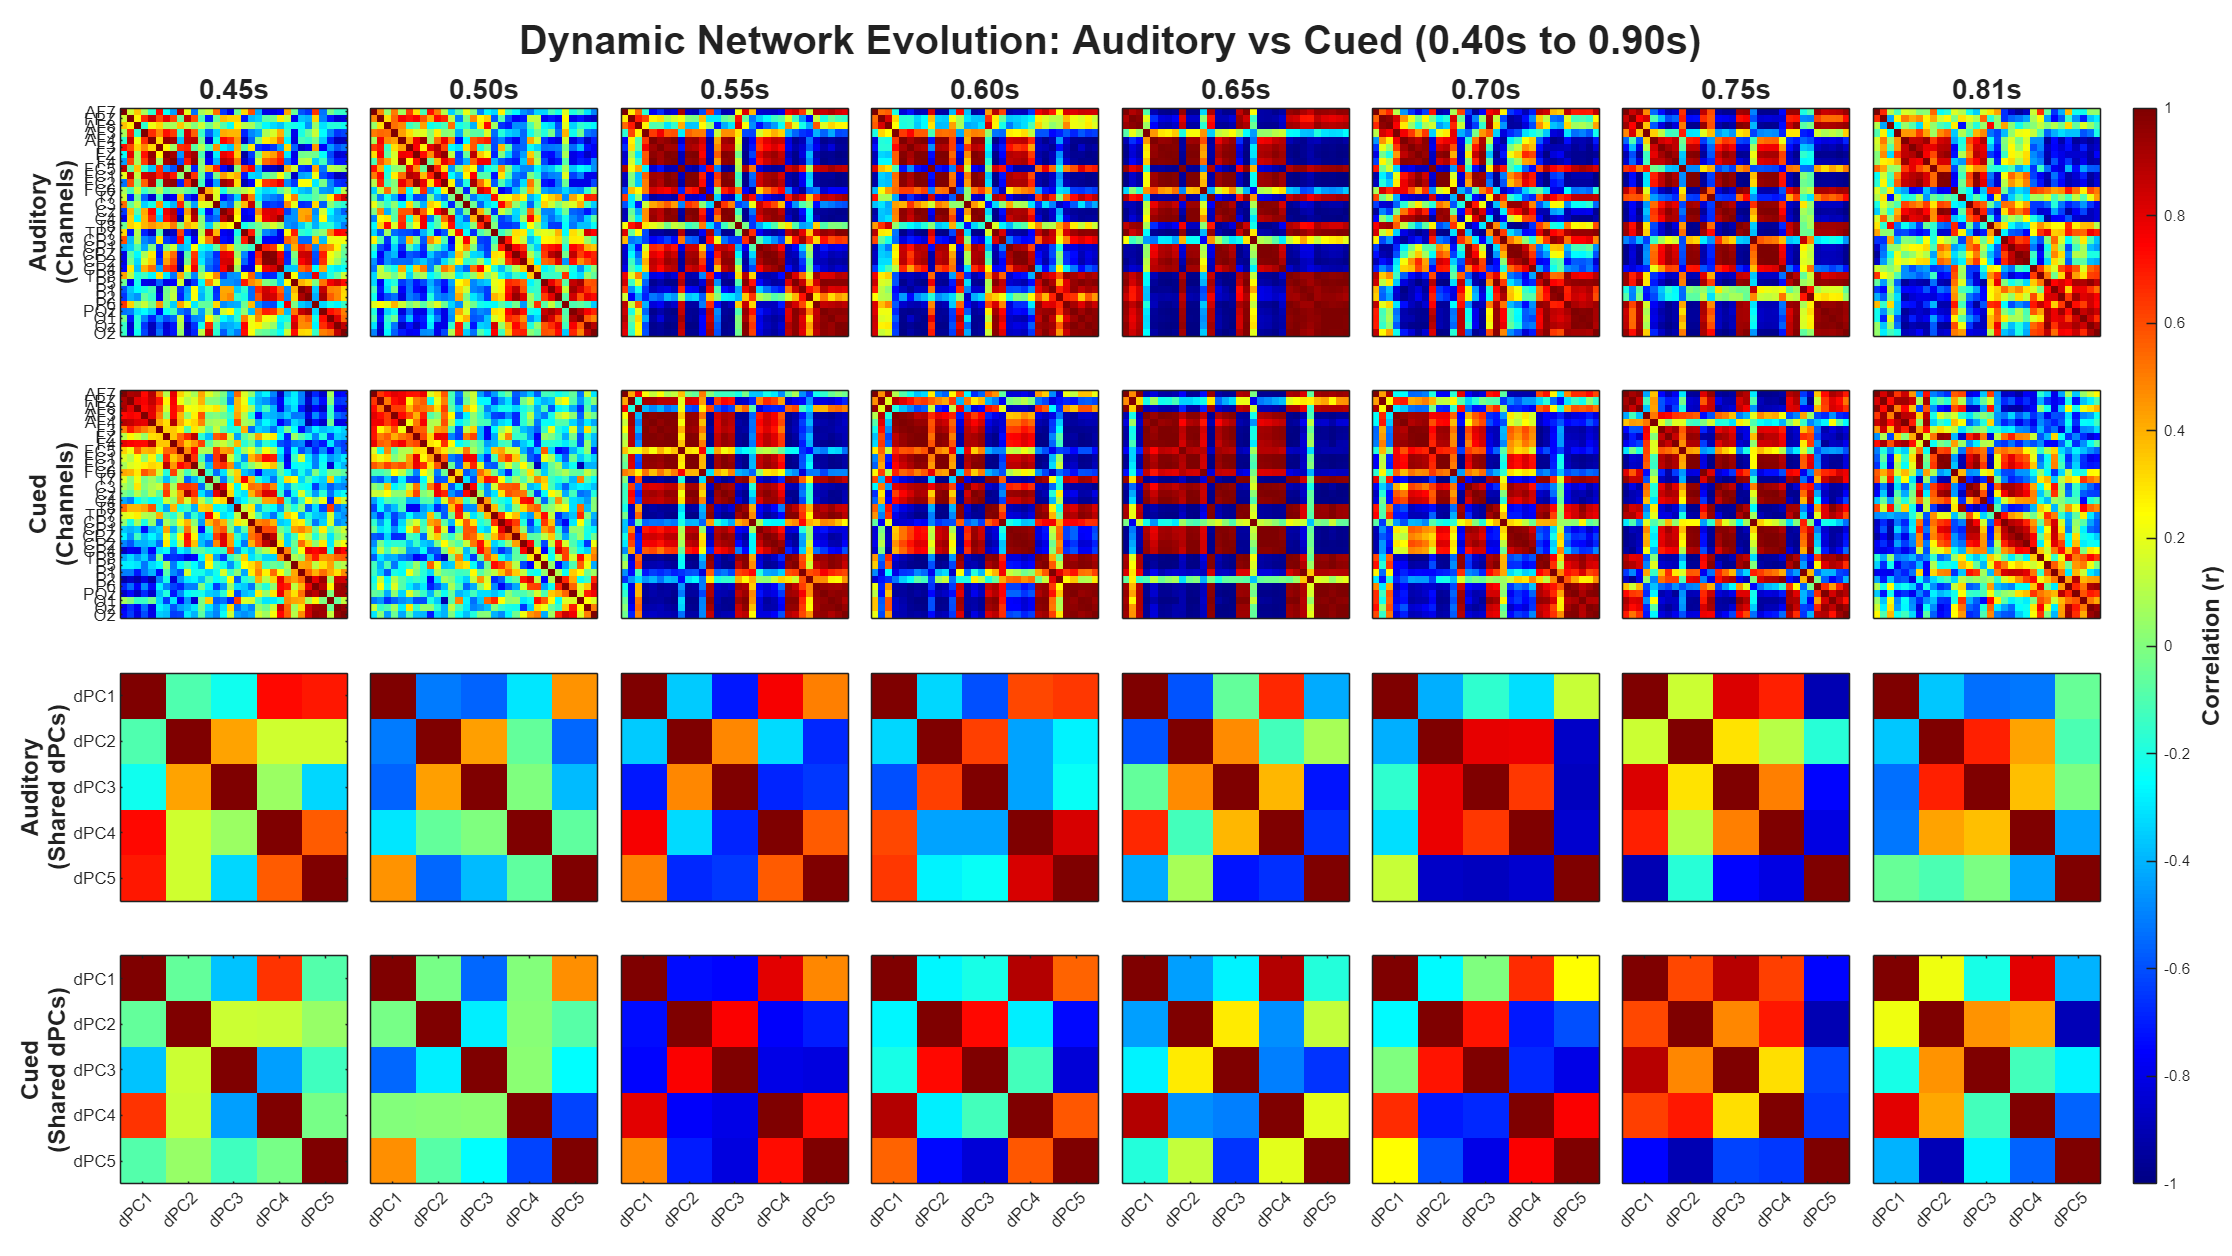

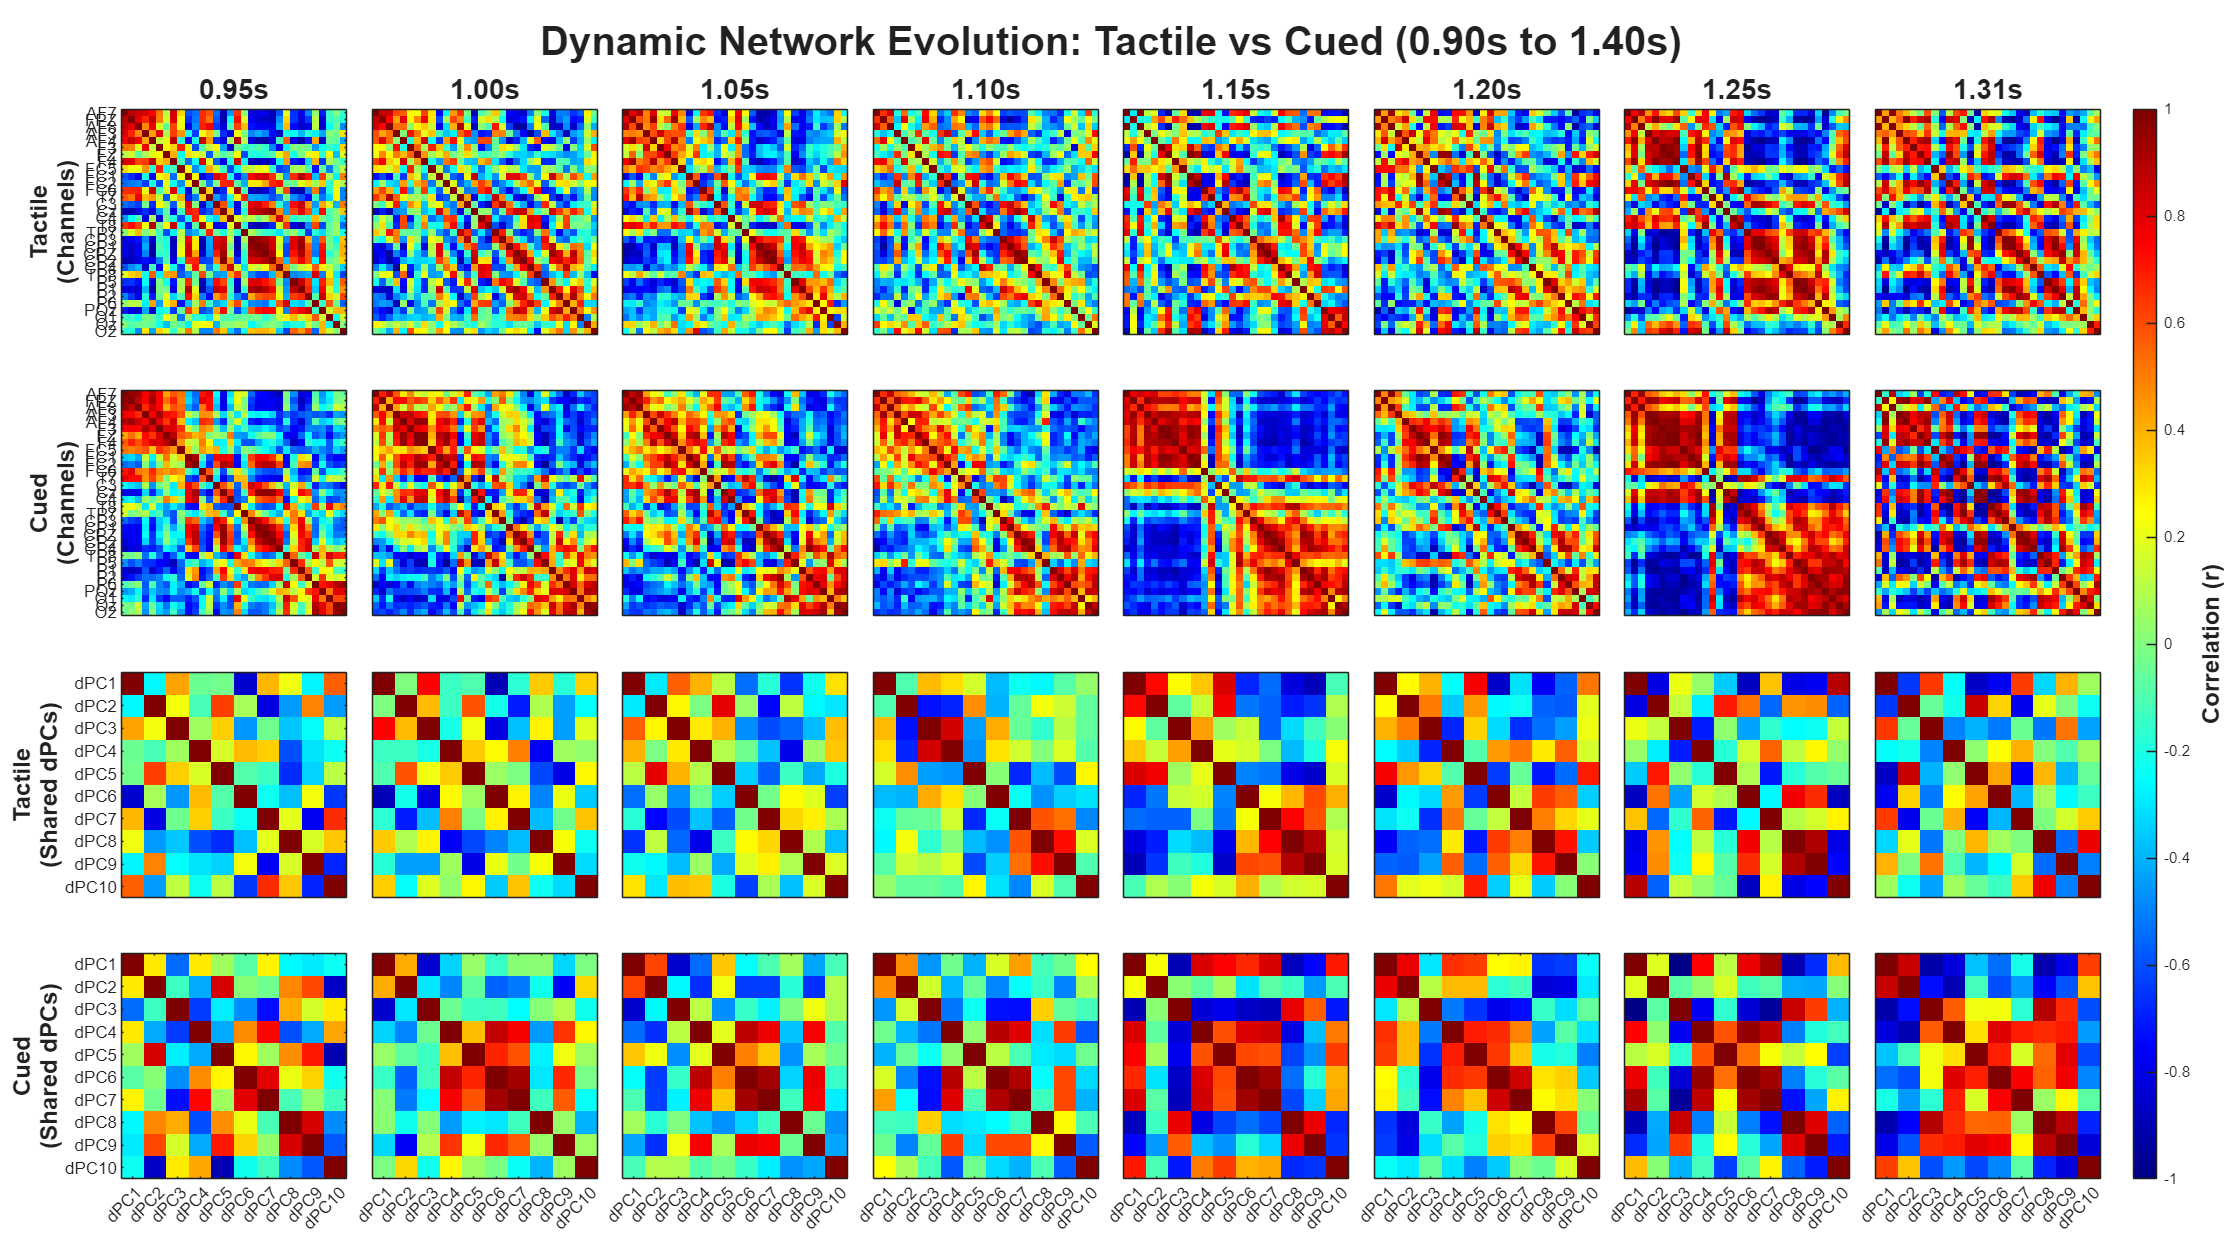

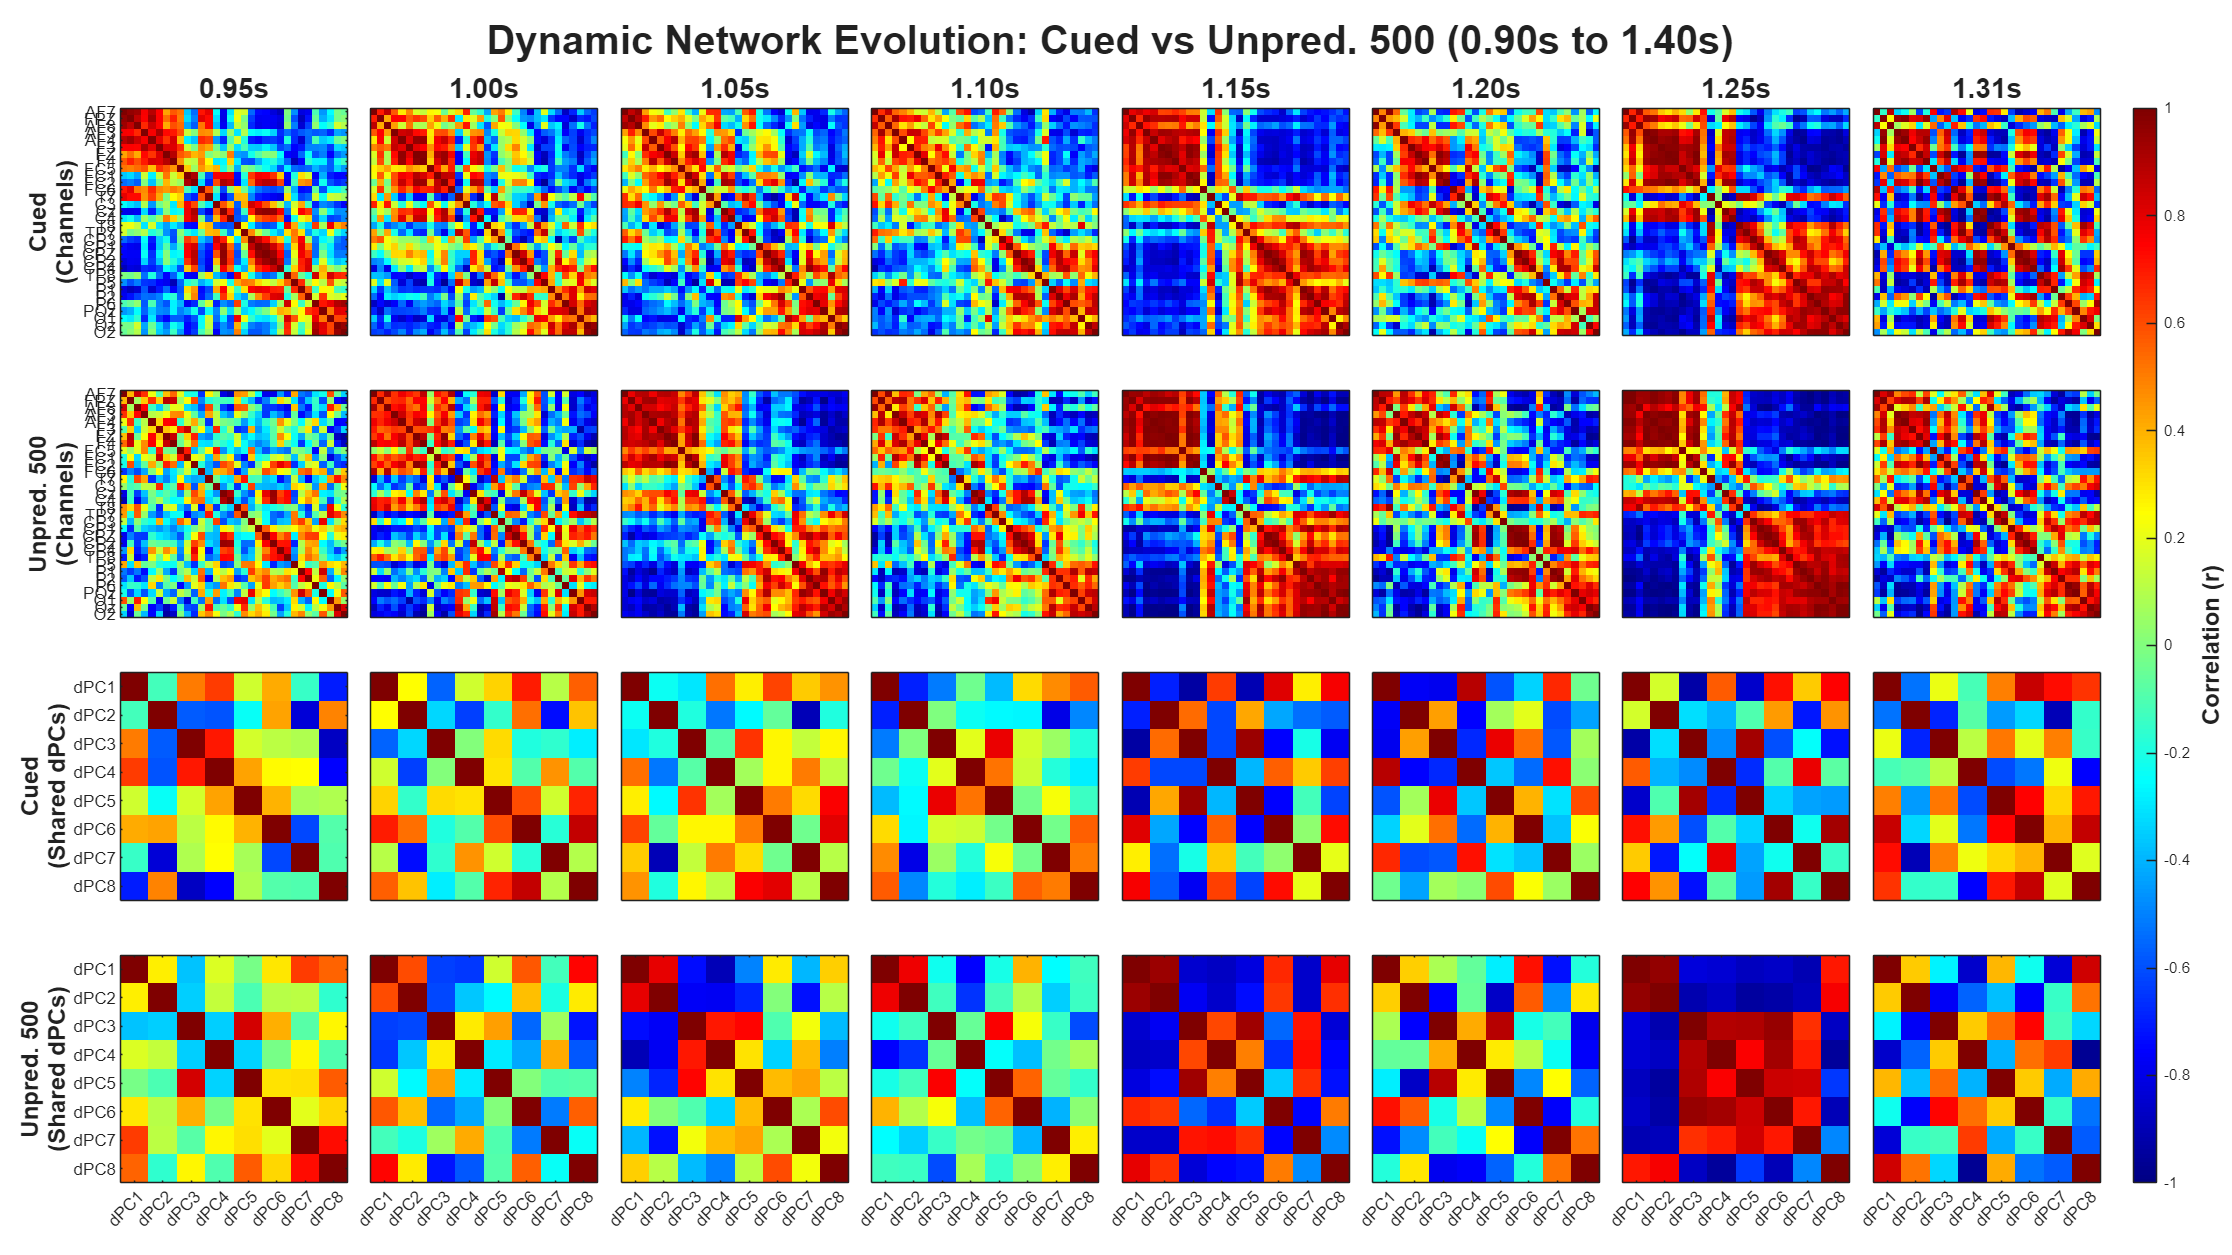

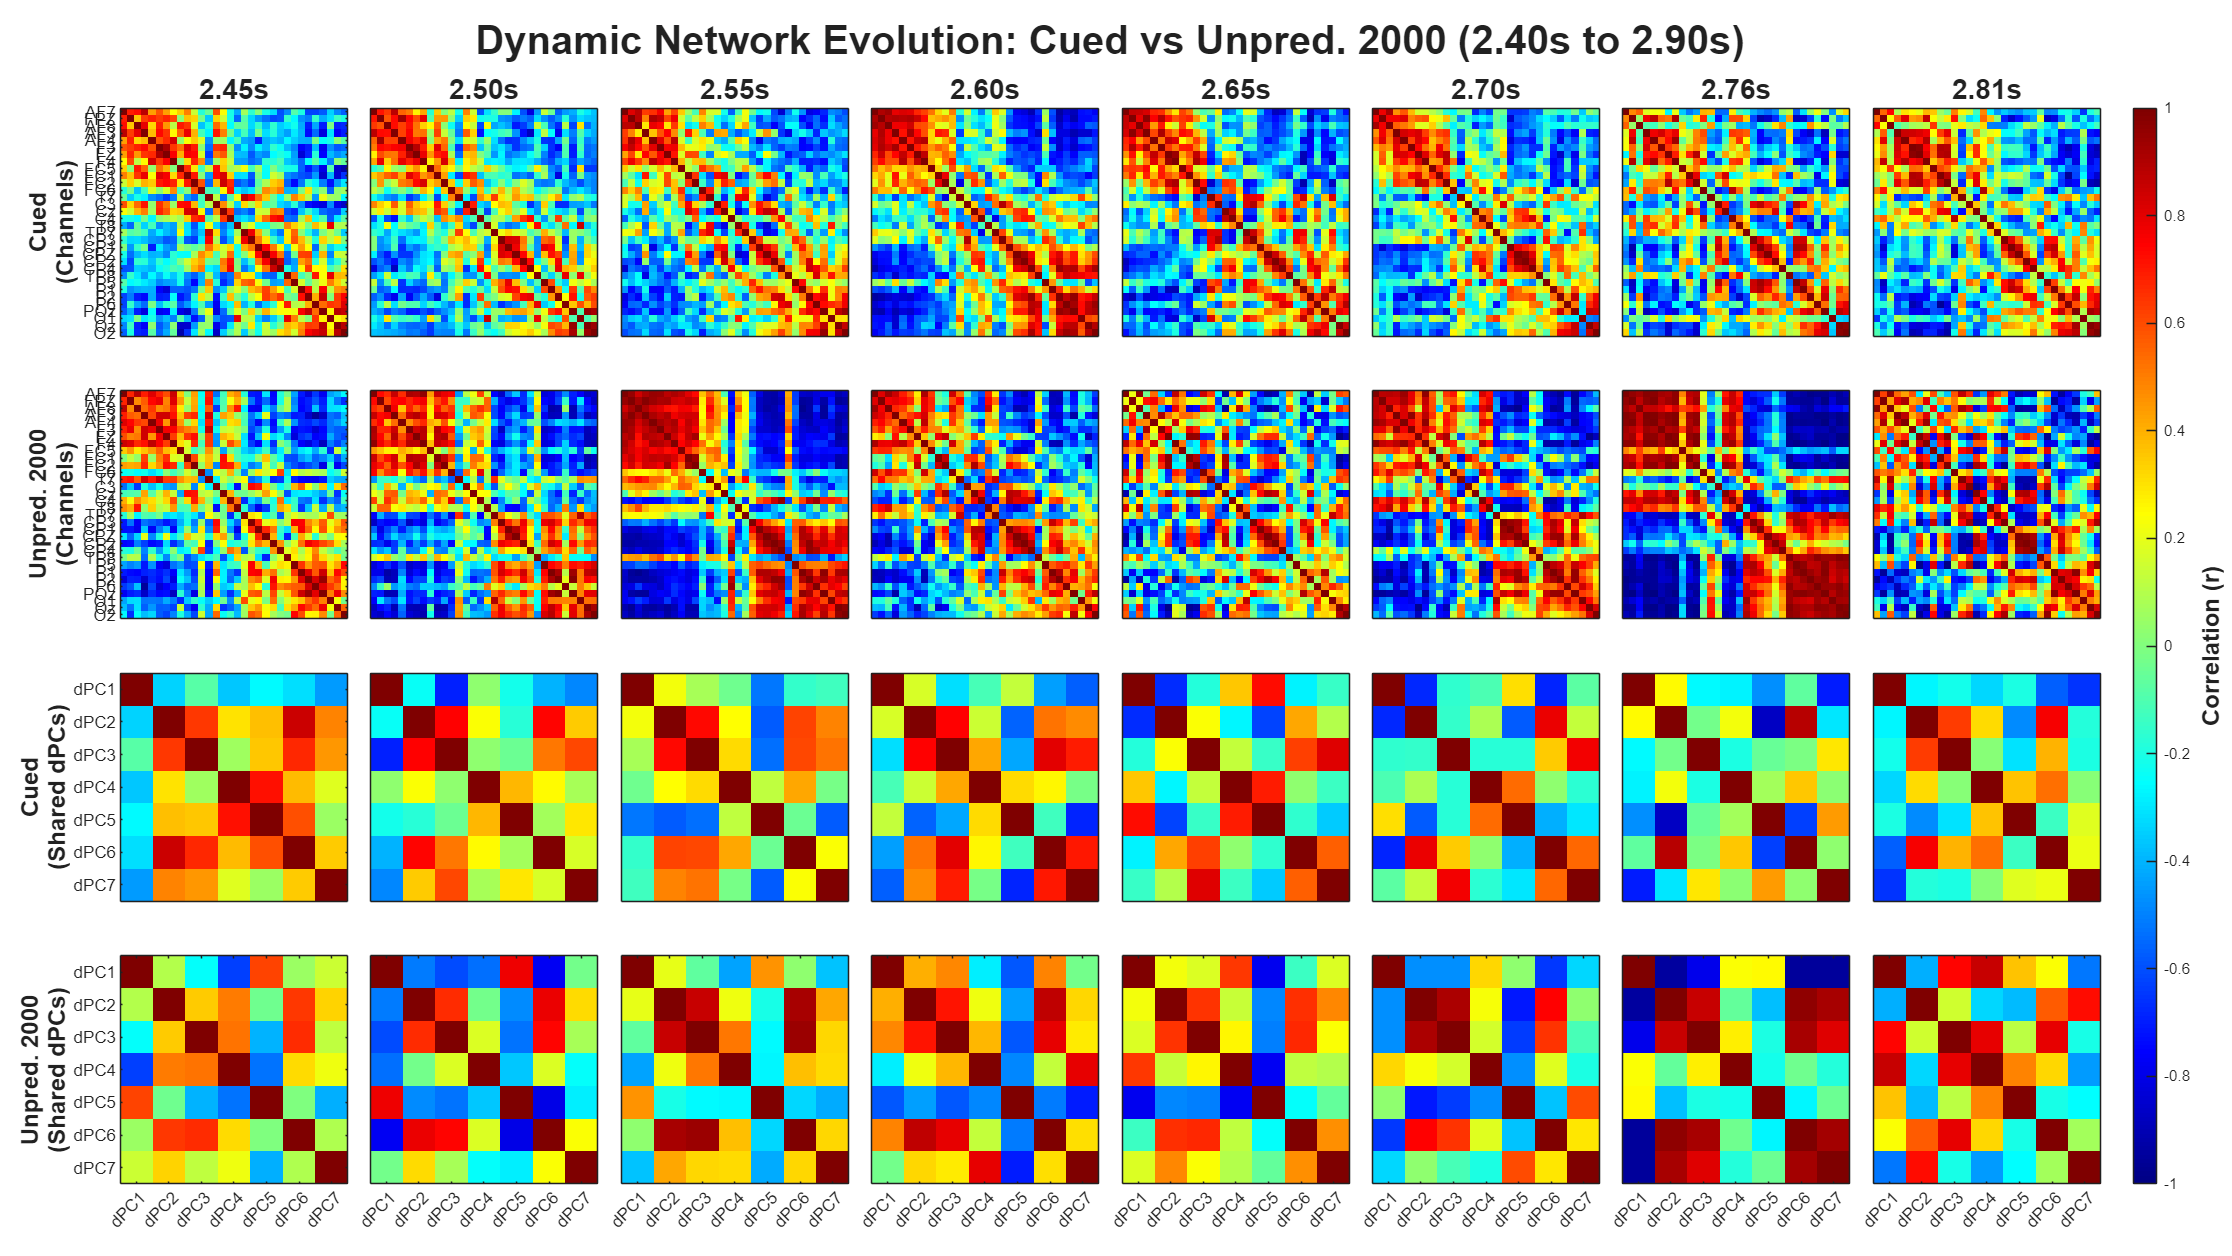

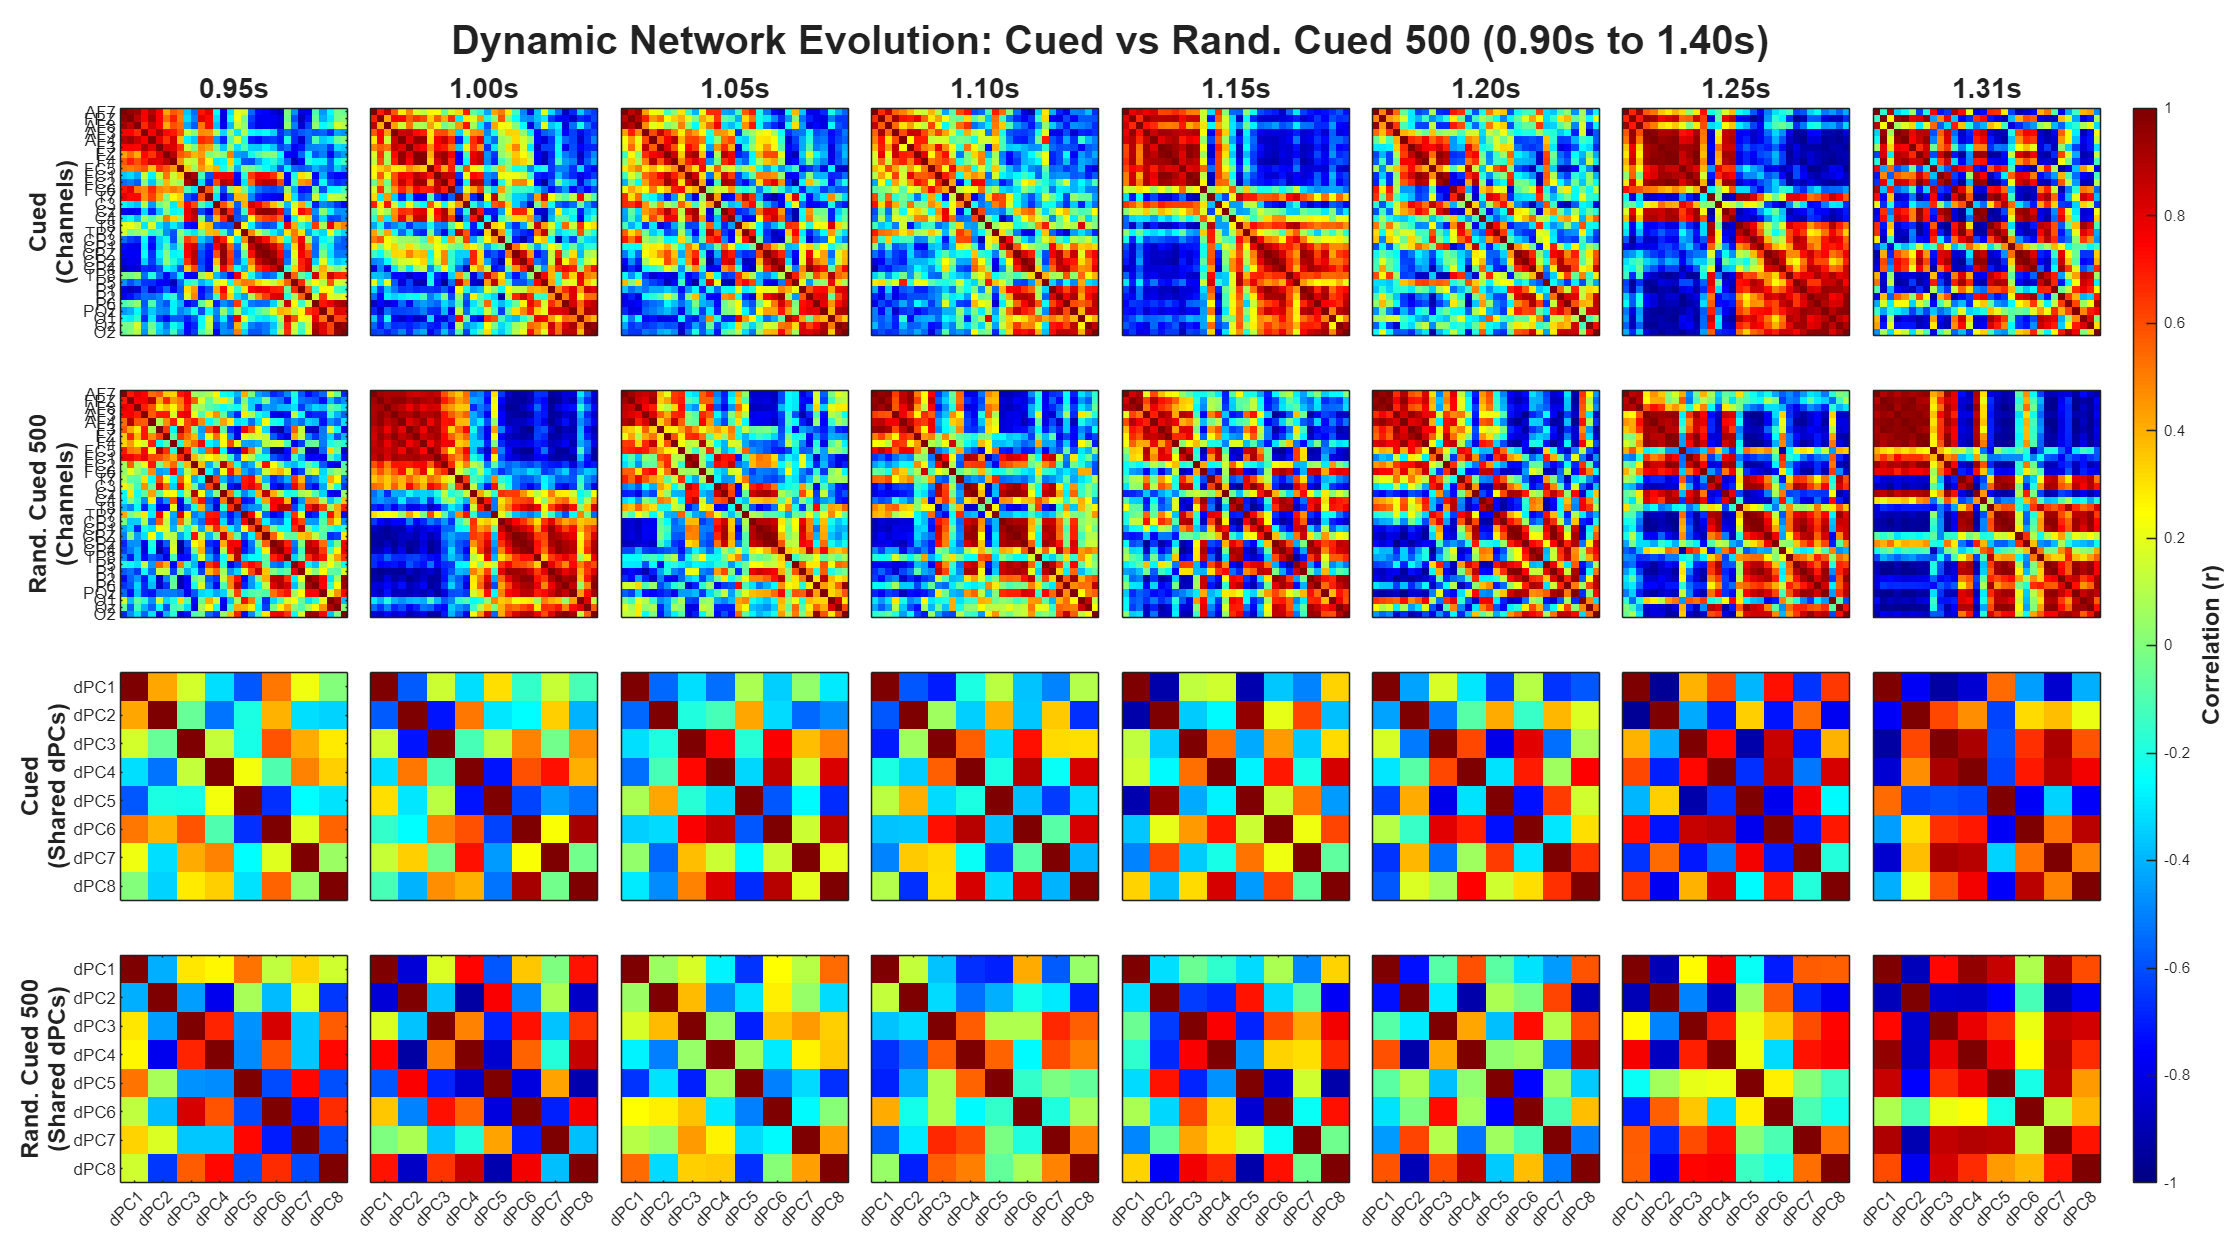

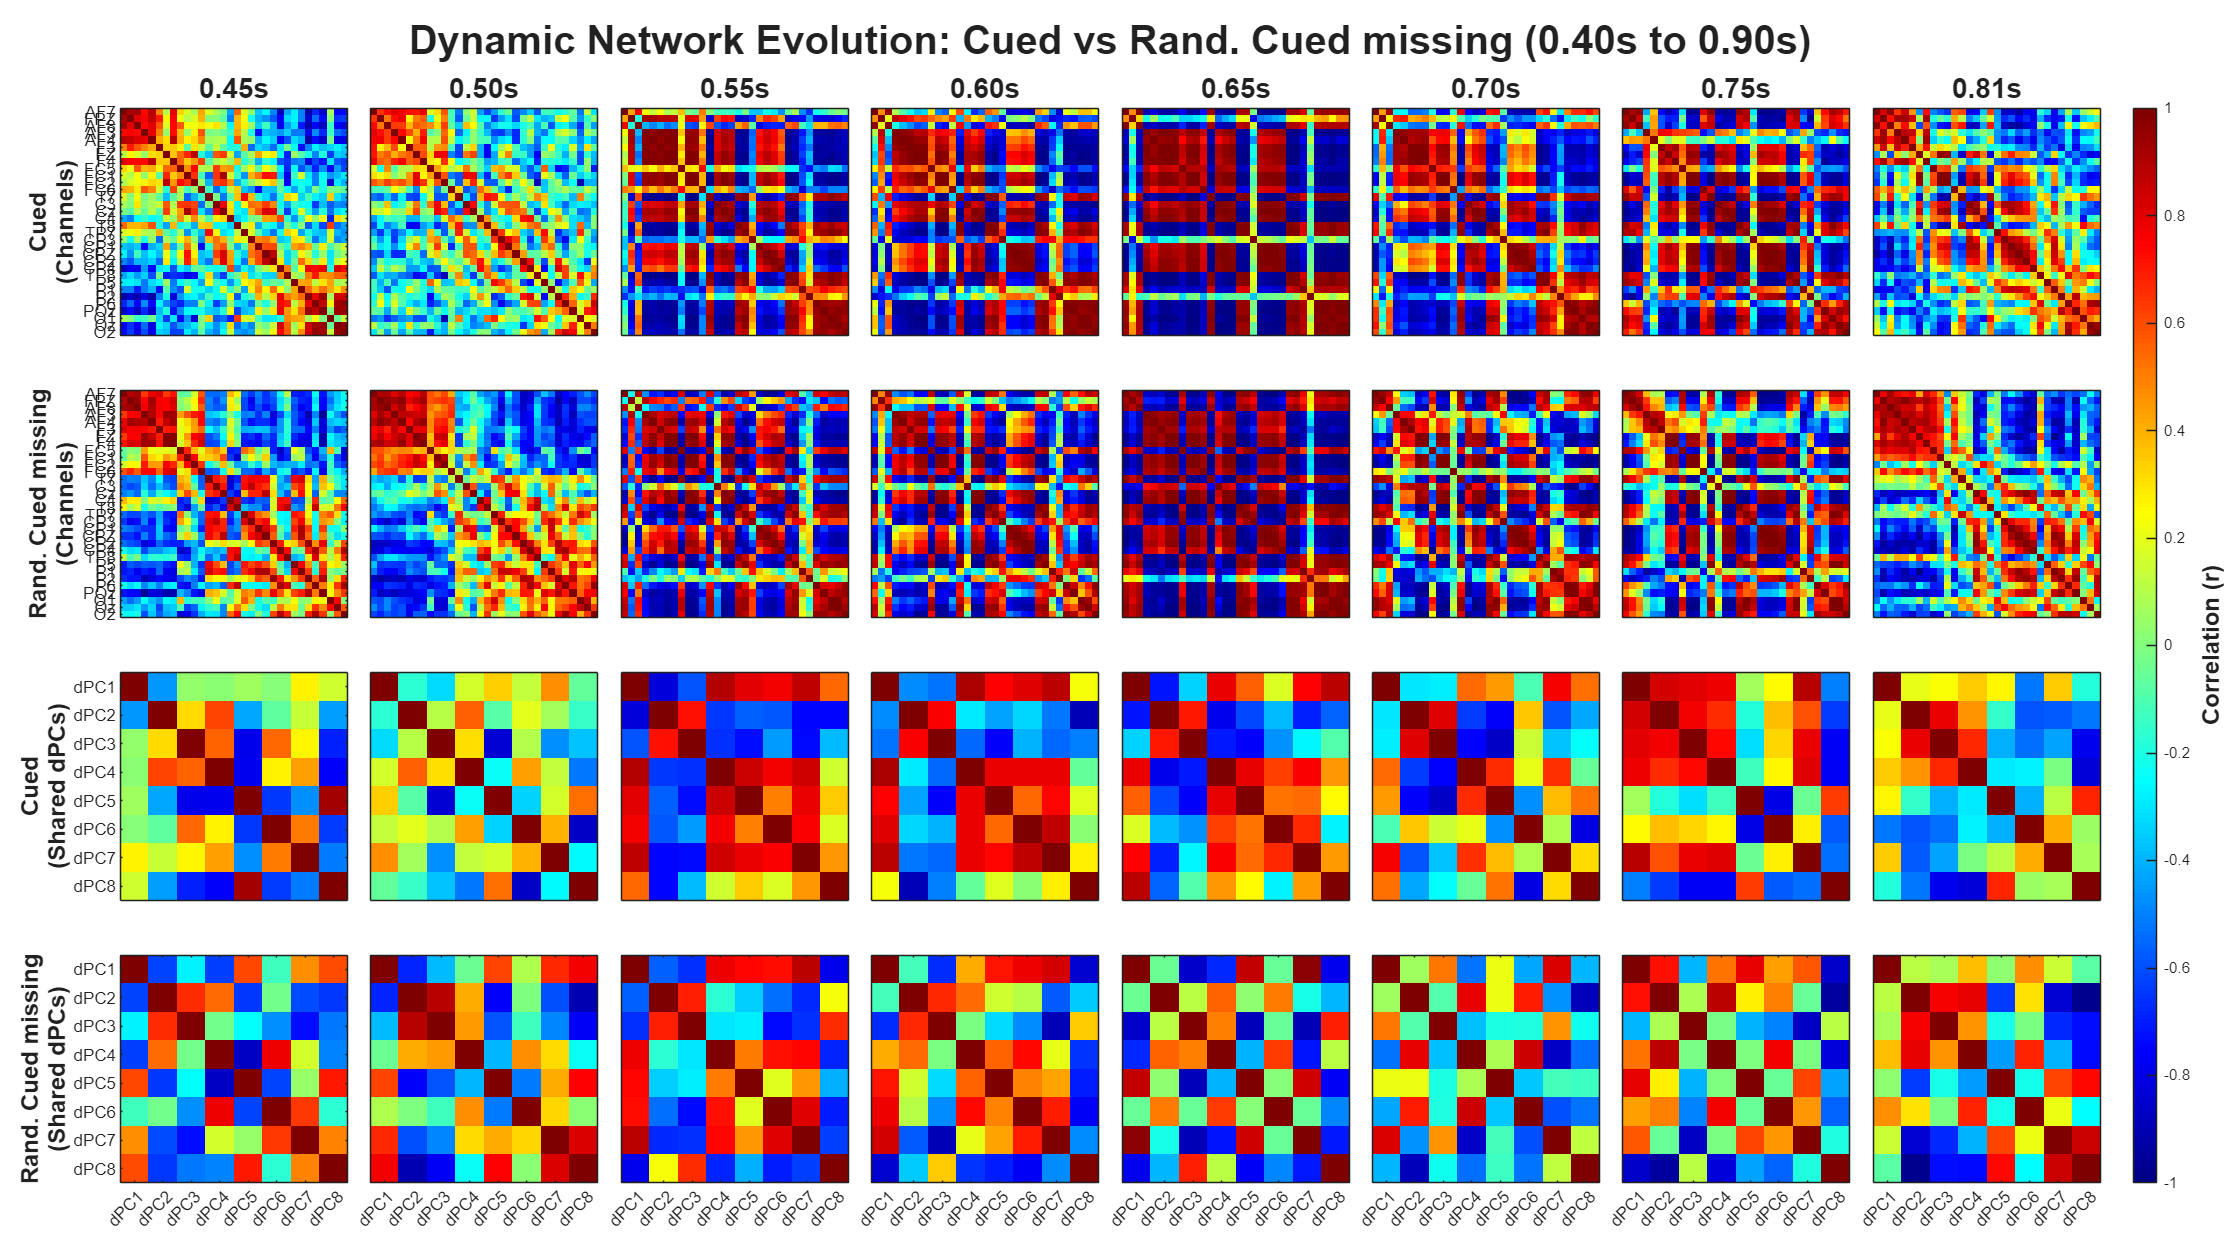


% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs and their specific time boundaries
pairs = {
    {'BLA', 'P1', [0.4, 0.9]},
    {'BLT', 'P1', [0.9, 1.4]},
    {'P1', 'P2_500', [0.9, 1.4]},
    {'P1', 'P2_2000', [2.4, 2.9]},
    {'P1', 'P3_500', [0.9, 1.4]},
    {'P1', 'P3_missing', [0.4, 0.9]}
};

target_subj = 1; % Analyzing Subject 1
if isempty(fs), fs = 500; end % Fallback for sampling rate

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % 1. Extract FULL Data for Global DR [Channels x Time]
    dataA_full = data_subj_avg.(condA)(:, :, target_subj);
    dataB_full = data_subj_avg.(condB)(:, :, target_subj);
    
    if all(isnan(dataA_full(:))) || all(isnan(dataB_full(:))), continue; end
    
    %% --- DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    % Find shared latent space across the entire epoch for stable axes
    data_combined = [dataA_full, dataB_full];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, dataA_full, dataB_full); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    % Project full data into Shared Latent Space
    compA_full = W * (dataA_full - mean(dataA_full, 2)); 
    compB_full = W * (dataB_full - mean(dataB_full, 2));
    
    %% --- ISOLATE SPECIFIC SUB-WINDOW FOR SLIDING HEATMAPS ---
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
    
    dataA_chunk = dataA_full(:, idx_start:idx_end);
    dataB_chunk = dataB_full(:, idx_start:idx_end);
    compA_chunk = compA_full(:, idx_start:idx_end);
    compB_chunk = compB_full(:, idx_start:idx_end);
    
    time_chunk = time_ms_eeg(idx_start:idx_end);
    num_chunk_points = size(dataA_chunk, 2);
    
    % Set up sliding indices for this specific chunk
    start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
    num_windows = length(start_idx);
    
    corr_ch_A_all = nan(num_ch, num_ch, num_windows);
    corr_ch_B_all = nan(num_ch, num_ch, num_windows);
    corr_pc_A_all = nan(k_opt, k_opt, num_windows);
    corr_pc_B_all = nan(k_opt, k_opt, num_windows);
    
    window_centers = zeros(1, num_windows);
    
    for w = 1:num_windows
        w_s = start_idx(w);
        w_e = w_s + win_samples - 1;
        
        window_centers(w) = mean(time_chunk(w_s:w_e));
        
        corr_ch_A_all(:,:,w) = corrcoef(dataA_chunk(:, w_s:w_e)');
        corr_ch_B_all(:,:,w) = corrcoef(dataB_chunk(:, w_s:w_e)');
        corr_pc_A_all(:,:,w) = corrcoef(compA_chunk(:, w_s:w_e)');
        corr_pc_B_all(:,:,w) = corrcoef(compB_chunk(:, w_s:w_e)');
    end
    
    %% --- PLOTTING FILMSTRIP SNAPSHOTS ---
    % Dynamically widen the figure based on how many windows we have (~200px per window)
    fig_width = max(1200, 200 * num_windows);
    fig = figure('Position', [50, 50, fig_width, 900], 'Name', sprintf('%s vs %s Filmstrip', cleanA, cleanB));
    tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % ROW 1: Condition A (Channels)
    for w = 1:num_windows
        nexttile; imagesc(corr_ch_A_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % ROW 2: Condition B (Channels)
    for w = 1:num_windows
        nexttile; imagesc(corr_ch_B_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 3: Condition A (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(corr_pc_A_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 4: Condition B (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(corr_pc_B_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks(1:k_opt); xticklabels(pc_labels); xtickangle(45);
    end
    
    % Master formatting
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('Dynamic Network Evolution: %s vs %s (%.2fs to %.2fs)', ...
        cleanA, cleanB, t_win(1), t_win(2)), 'FontSize', 20, 'FontWeight', 'bold');
        
    % Optional: Save figure directly to output path
    % saveas(fig, fullfile(output_path, sprintf('Filmstrip_%s_vs_%s.png', condA, condB)));
end


disp('Filmstrip Heatmaps generated successfully.');

Filmstrip Heatmaps generated successfully.


Dynamic Pairwise Connectivity calculated and plotted.
